# DL draft

(Section 4)

github@hnxj; github@dynasim

## 0. Initialization

clear;close all;clc;
PathToDynaSim = 'D:\Modeling\'; % Change it based on your local path for dynasim 
cd(PathToDynaSim);
addpath(genpath('DynaSim'));
cd('DynaSim');

## 1.Neural circuit structure in Dynasim

PINH: Pyramidal-INterneuron Harmony circuit.

study_dir = 'dlModels/PN14';

eqns={
  ['dV/dt = (Iapp*rand(1, N_pop)*(cos(t*omega).^2)*((t > t0) & (t < t1)))' ...
  ' + @current + noise*randn(1, N_pop); noise = 0; t0 = 550; t1 = 950; omega = .2;' ...
  ' Iapp = 0; V(0) = -50*rand(1, N_pop);']
};
% Control current drive for direct stimulation purposes

nEx = 36;
nIl = 7;
nIg = 7;

% nRti = ceil(nIl/nEx);

gGABAslow = 0.25; % Receptor conductances, will be modulated by synaptic conn.
gGABAfast = 0.25;
gAMPAfar = 0.25;

gGABA = 0.25;
gAMPA = 0.25;
tauGain = 25;

% All receptor synaptic decay time constants are from the same dist. 
tauGABAslow = tauGain*(1 + .1*randn(1)); % SST->~20Hz ~(1/2t = 1/100)
tauGABAfast = tauGain*(1 + .1*randn(1)); % PV->~20Hz (1/10)
tauAMPAnear = tauGain*(1 + .1*randn(1)); % PY->~20.0Hz (1/20)
tauAMPAfar = tauGain*(1 + .1*randn(1)); % PY->~20.0Hz (1/40)

iNoise = 50;
eNoise = iNoise*1.0;
fNoise = iNoise*1.0;
sNoise = iNoise*1.0;

% gleakEx = 0.001;
% gleakIl = 0.001;
% gleakIg = 0.001;

cCoeff = 1.0;
cCoeffx = 1.0;
cConst = 0.1;

kEE = rand(nEx, nEx) * cCoeffx + cConst;
kEIf = rand(nEx, nIl) * cCoeff + cConst;
kEIs = rand(nEx, nIg) * cCoeff + cConst;

kIfE = rand(nIl, nEx) * cCoeff + cConst;
kIfIf = rand(nIl, nIl) * cCoeffx + cConst;
kIfIs = rand(nIl, nIg) * cCoeff + cConst;

kIsE = rand(nIg, nEx) * cCoeff + cConst;
kIsIf = rand(nIg, nIl) * cCoeff + cConst;
kIsIs = rand(nIg, nIg) * cCoeffx + cConst;

s=[];
s.populations(1).name='EXc';
s.populations(1).size=nEx;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK', 'ileak'};
s.populations(1).parameters={'gNa',120,'gK',36,'noise',eNoise};

s.populations(2).name='INl';
s.populations(2).size=nIl;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK', 'ileak'};
s.populations(2).parameters={'gNa',120,'gK',36,'noise',fNoise};

s.populations(3).name='INg';
s.populations(3).size=nIg;
s.populations(3).equations=eqns;
s.populations(3).mechanism_list={'iNa','iK', 'ileak'};
s.populations(3).parameters={'gNa',120,'gK',36,'noise',sNoise};

s.connections(1).direction='INl->EXc';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIfE};

s.connections(2).direction='EXc->INl';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPAnear,'gAMPA',gAMPAfar, 'netcon', kEIf};

s.connections(3).direction='INg->EXc';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kIsE};

s.connections(4).direction='EXc->INg';
s.connections(4).mechanism_list={'iAMPA'};
s.connections(4).parameters={'tauD',tauAMPAfar,'gAMPA',gAMPAfar, 'netcon', kEIs};

s.connections(5).direction='INg->INl';
s.connections(5).mechanism_list={'iGABAa'};
s.connections(5).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kIsIf};

s.connections(6).direction='INg->INg';
s.connections(6).mechanism_list={'iGABAa'};
s.connections(6).parameters={'tauD', tauGABAslow,'gGABAa',gGABA, 'netcon', kIsIs};

s.connections(7).direction='INl->INg';
s.connections(7).mechanism_list={'iGABAa'};
s.connections(7).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIfIs};

s.connections(8).direction='INl->INl';
s.connections(8).mechanism_list={'iGABAa'};
s.connections(8).parameters={'tauD',tauGABAfast,'gGABAa',gGABA, 'netcon', kIfIf};

s.connections(9).direction='EXc->EXc';
s.connections(9).mechanism_list={'iAMPA'};
s.connections(9).parameters={'tauD',tauAMPAnear,'gAMPA',gAMPA, 'netcon', kEE};

RunDuration = 1500; % In ms (miliseconds) 
vary = {'Iapp', [0 50]};

tic;
data = dsSimulate(s, 'tspan', [0 RunDuration], 'downsample_factor', 10, ...
                     'dt', .1, 'study_dir', '/dlSim/dlSim28', ...
                     'compile_flag', 0, 'parallel_flag', 0, ...
                     'vary', vary, 'verbose_flag', 0);
toc;

Elapsed time is 17.729956 seconds.


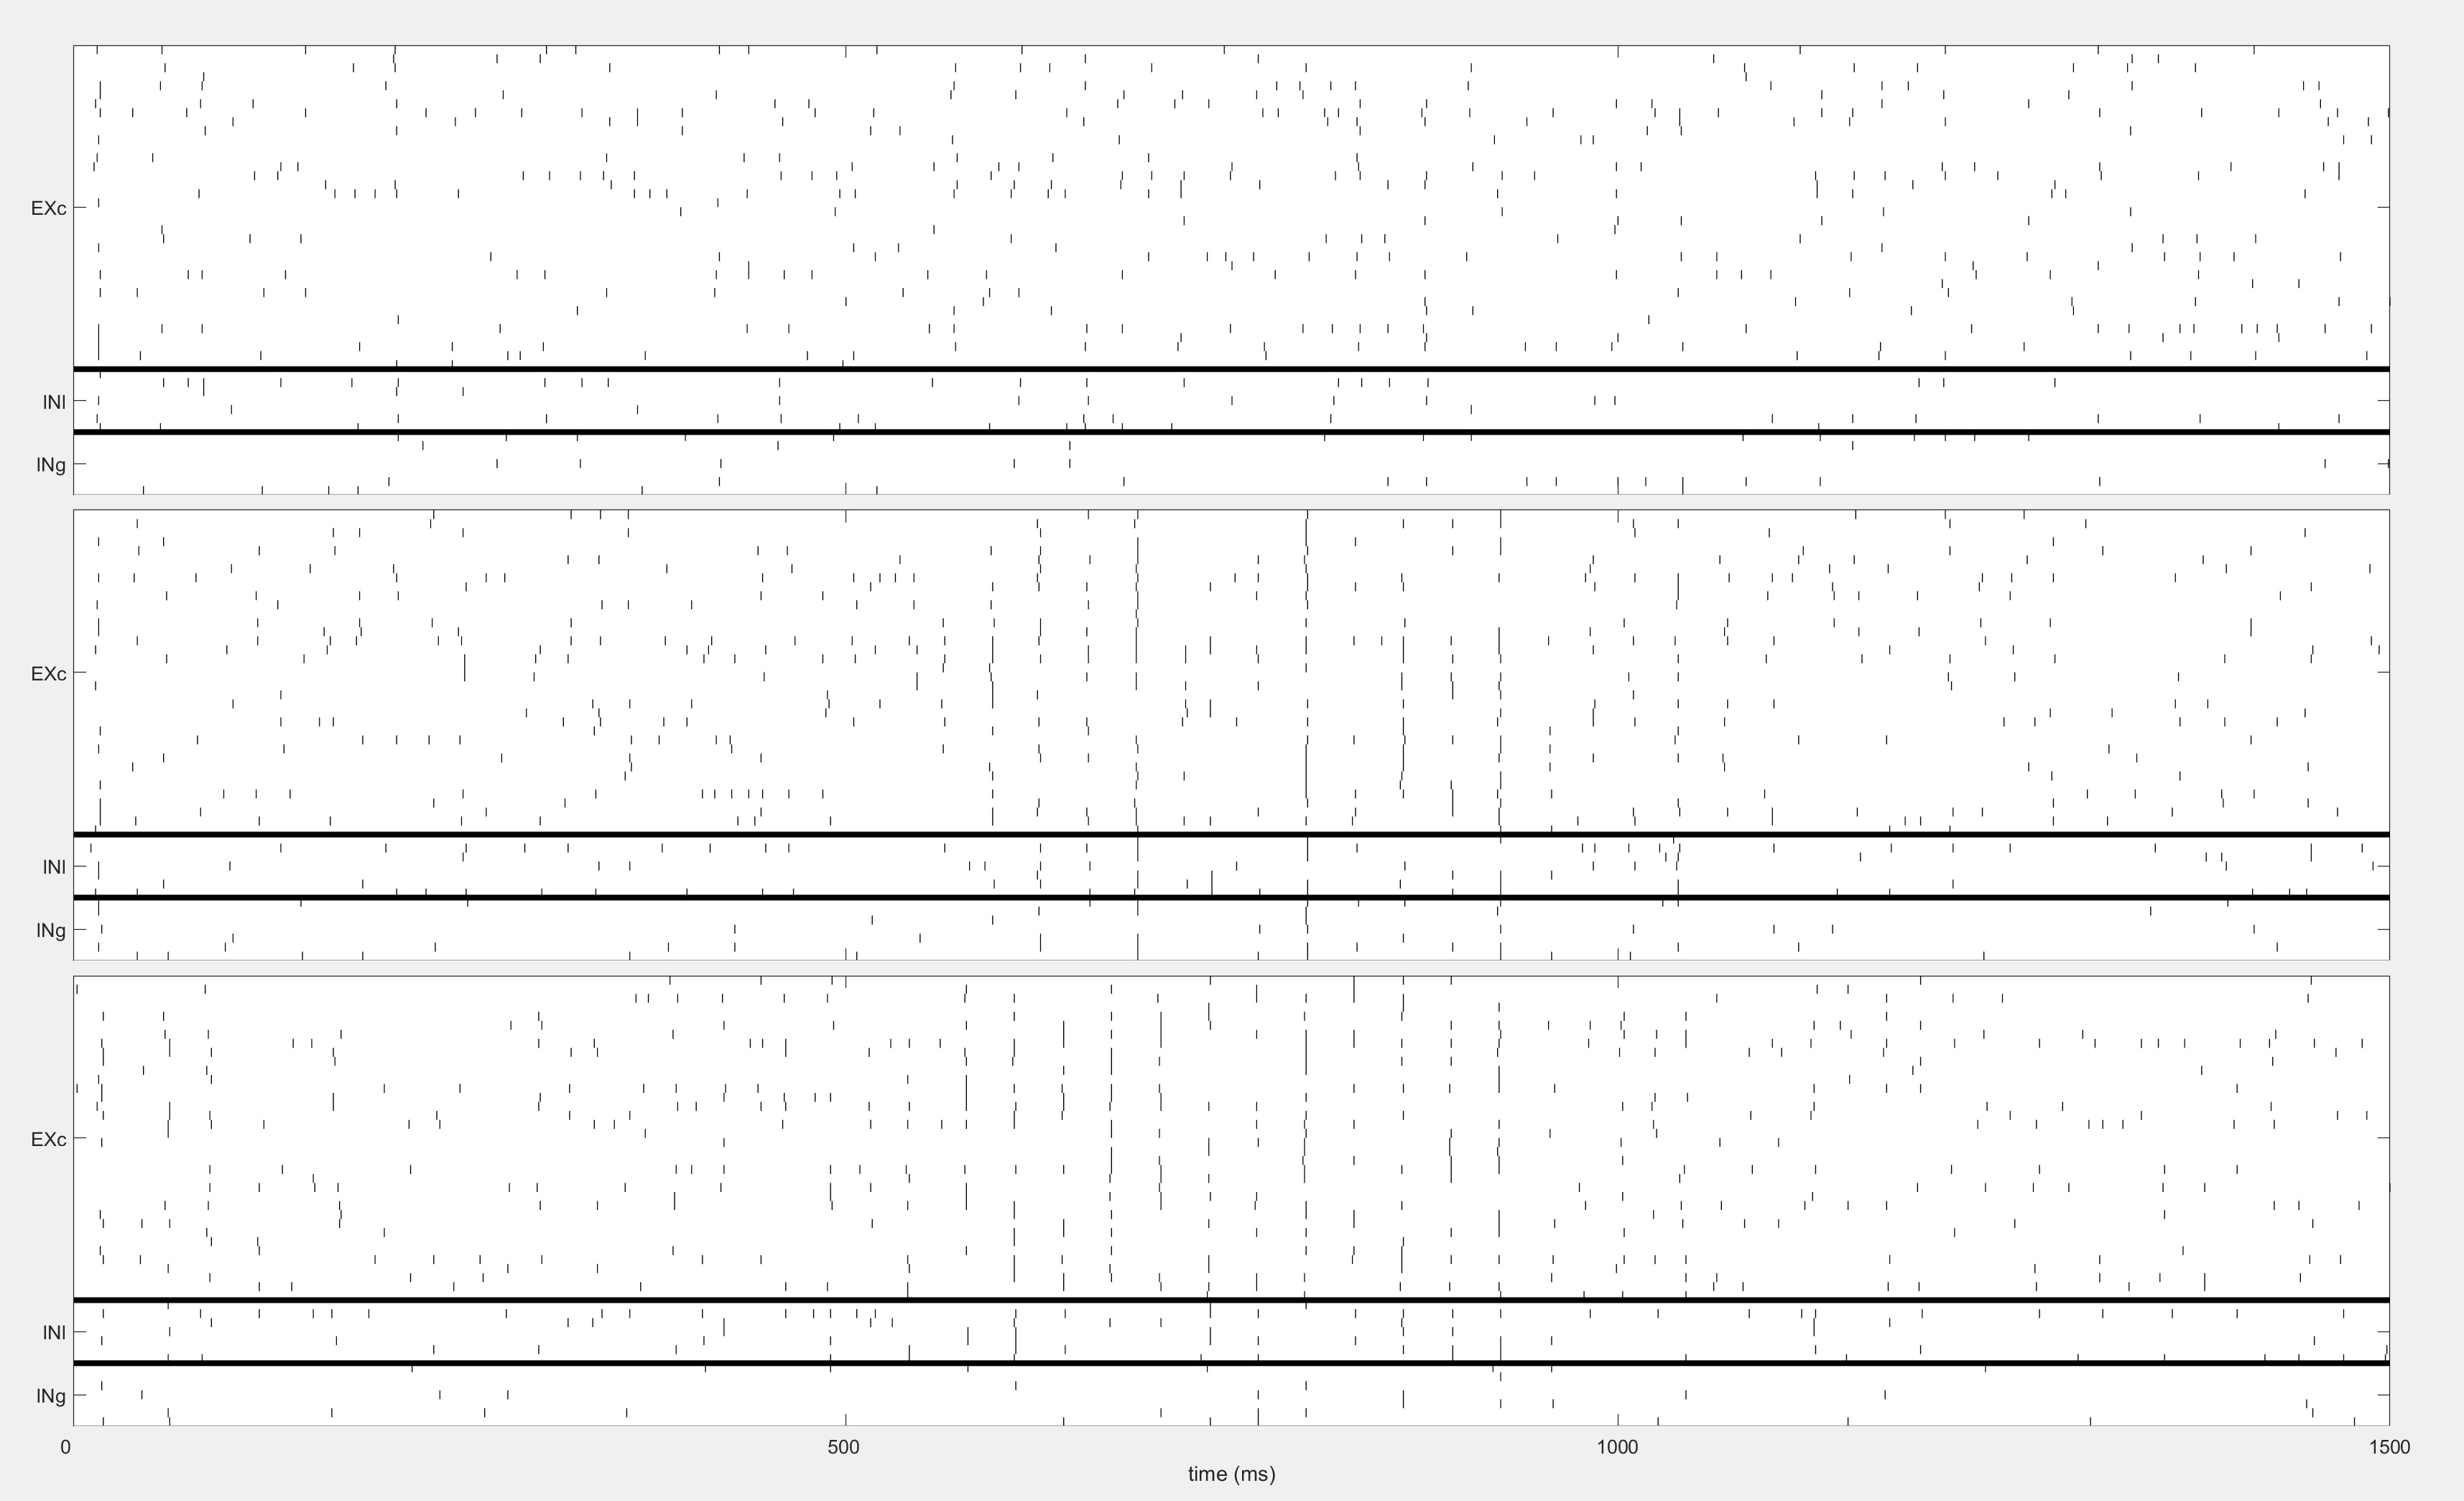

dsPlot(data, 'plot_type', 'raster', 'threshold', -10);

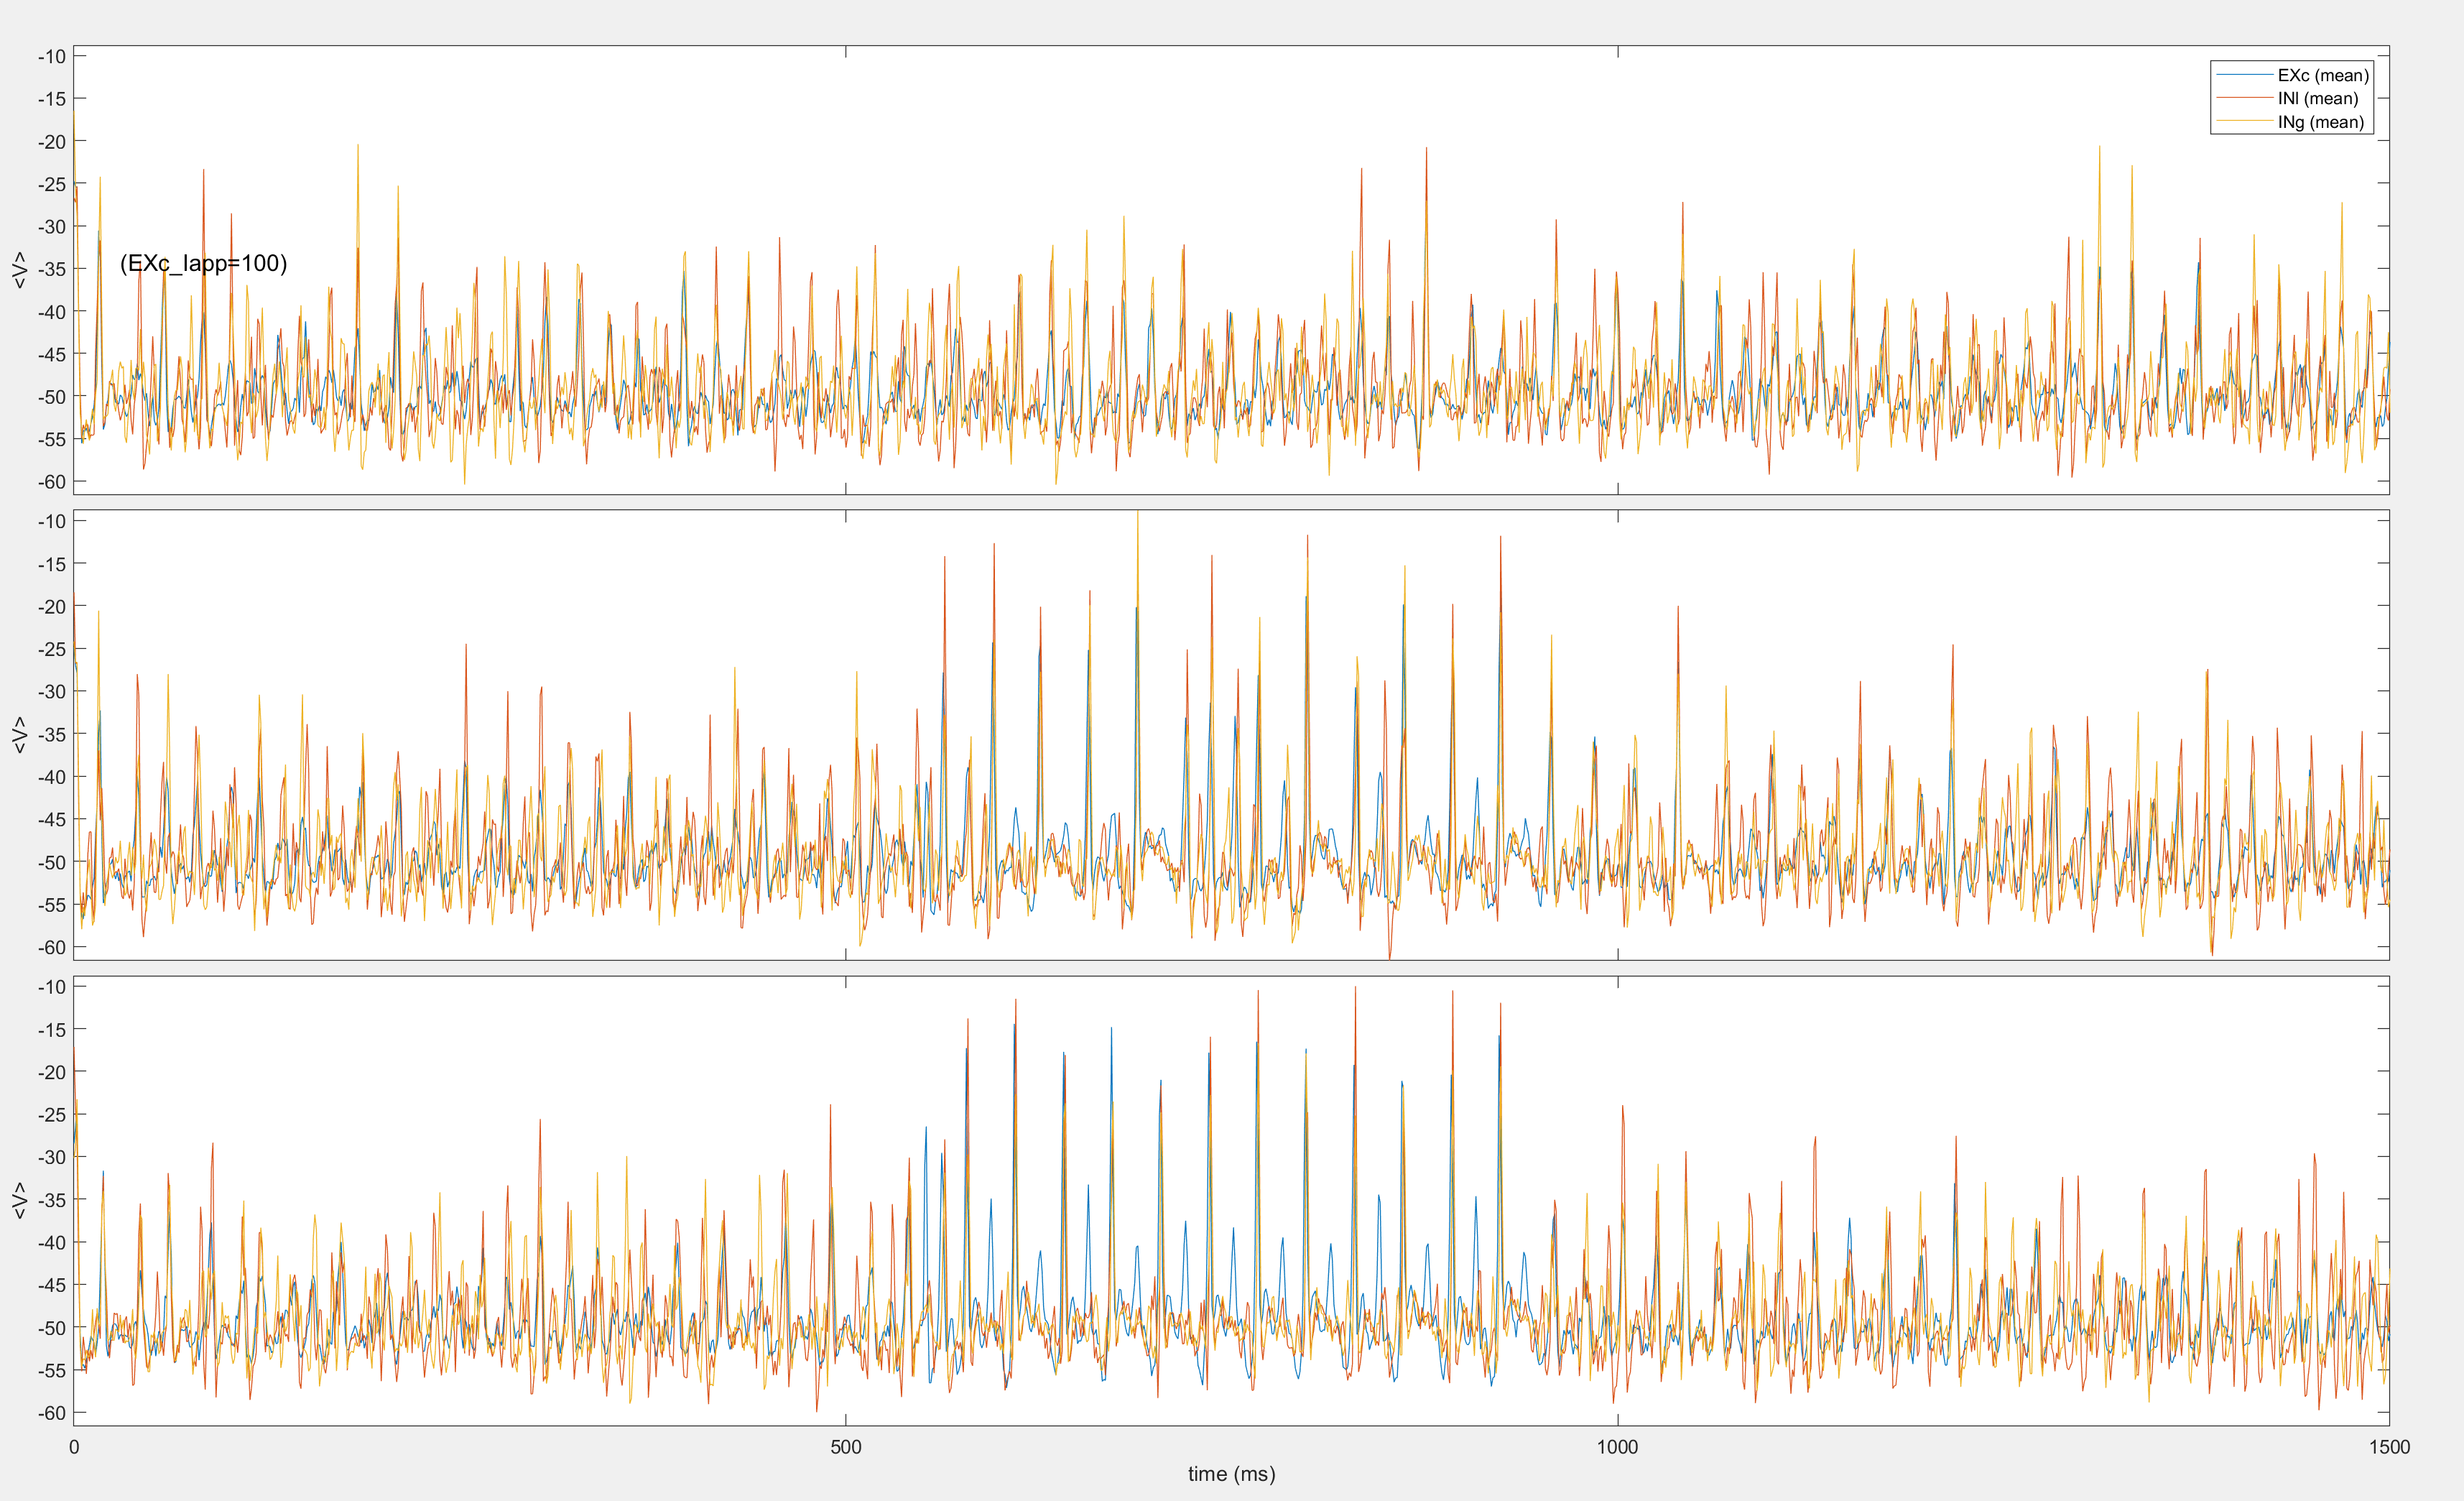

dsPlot(data, 'plot_type', 'waveform');

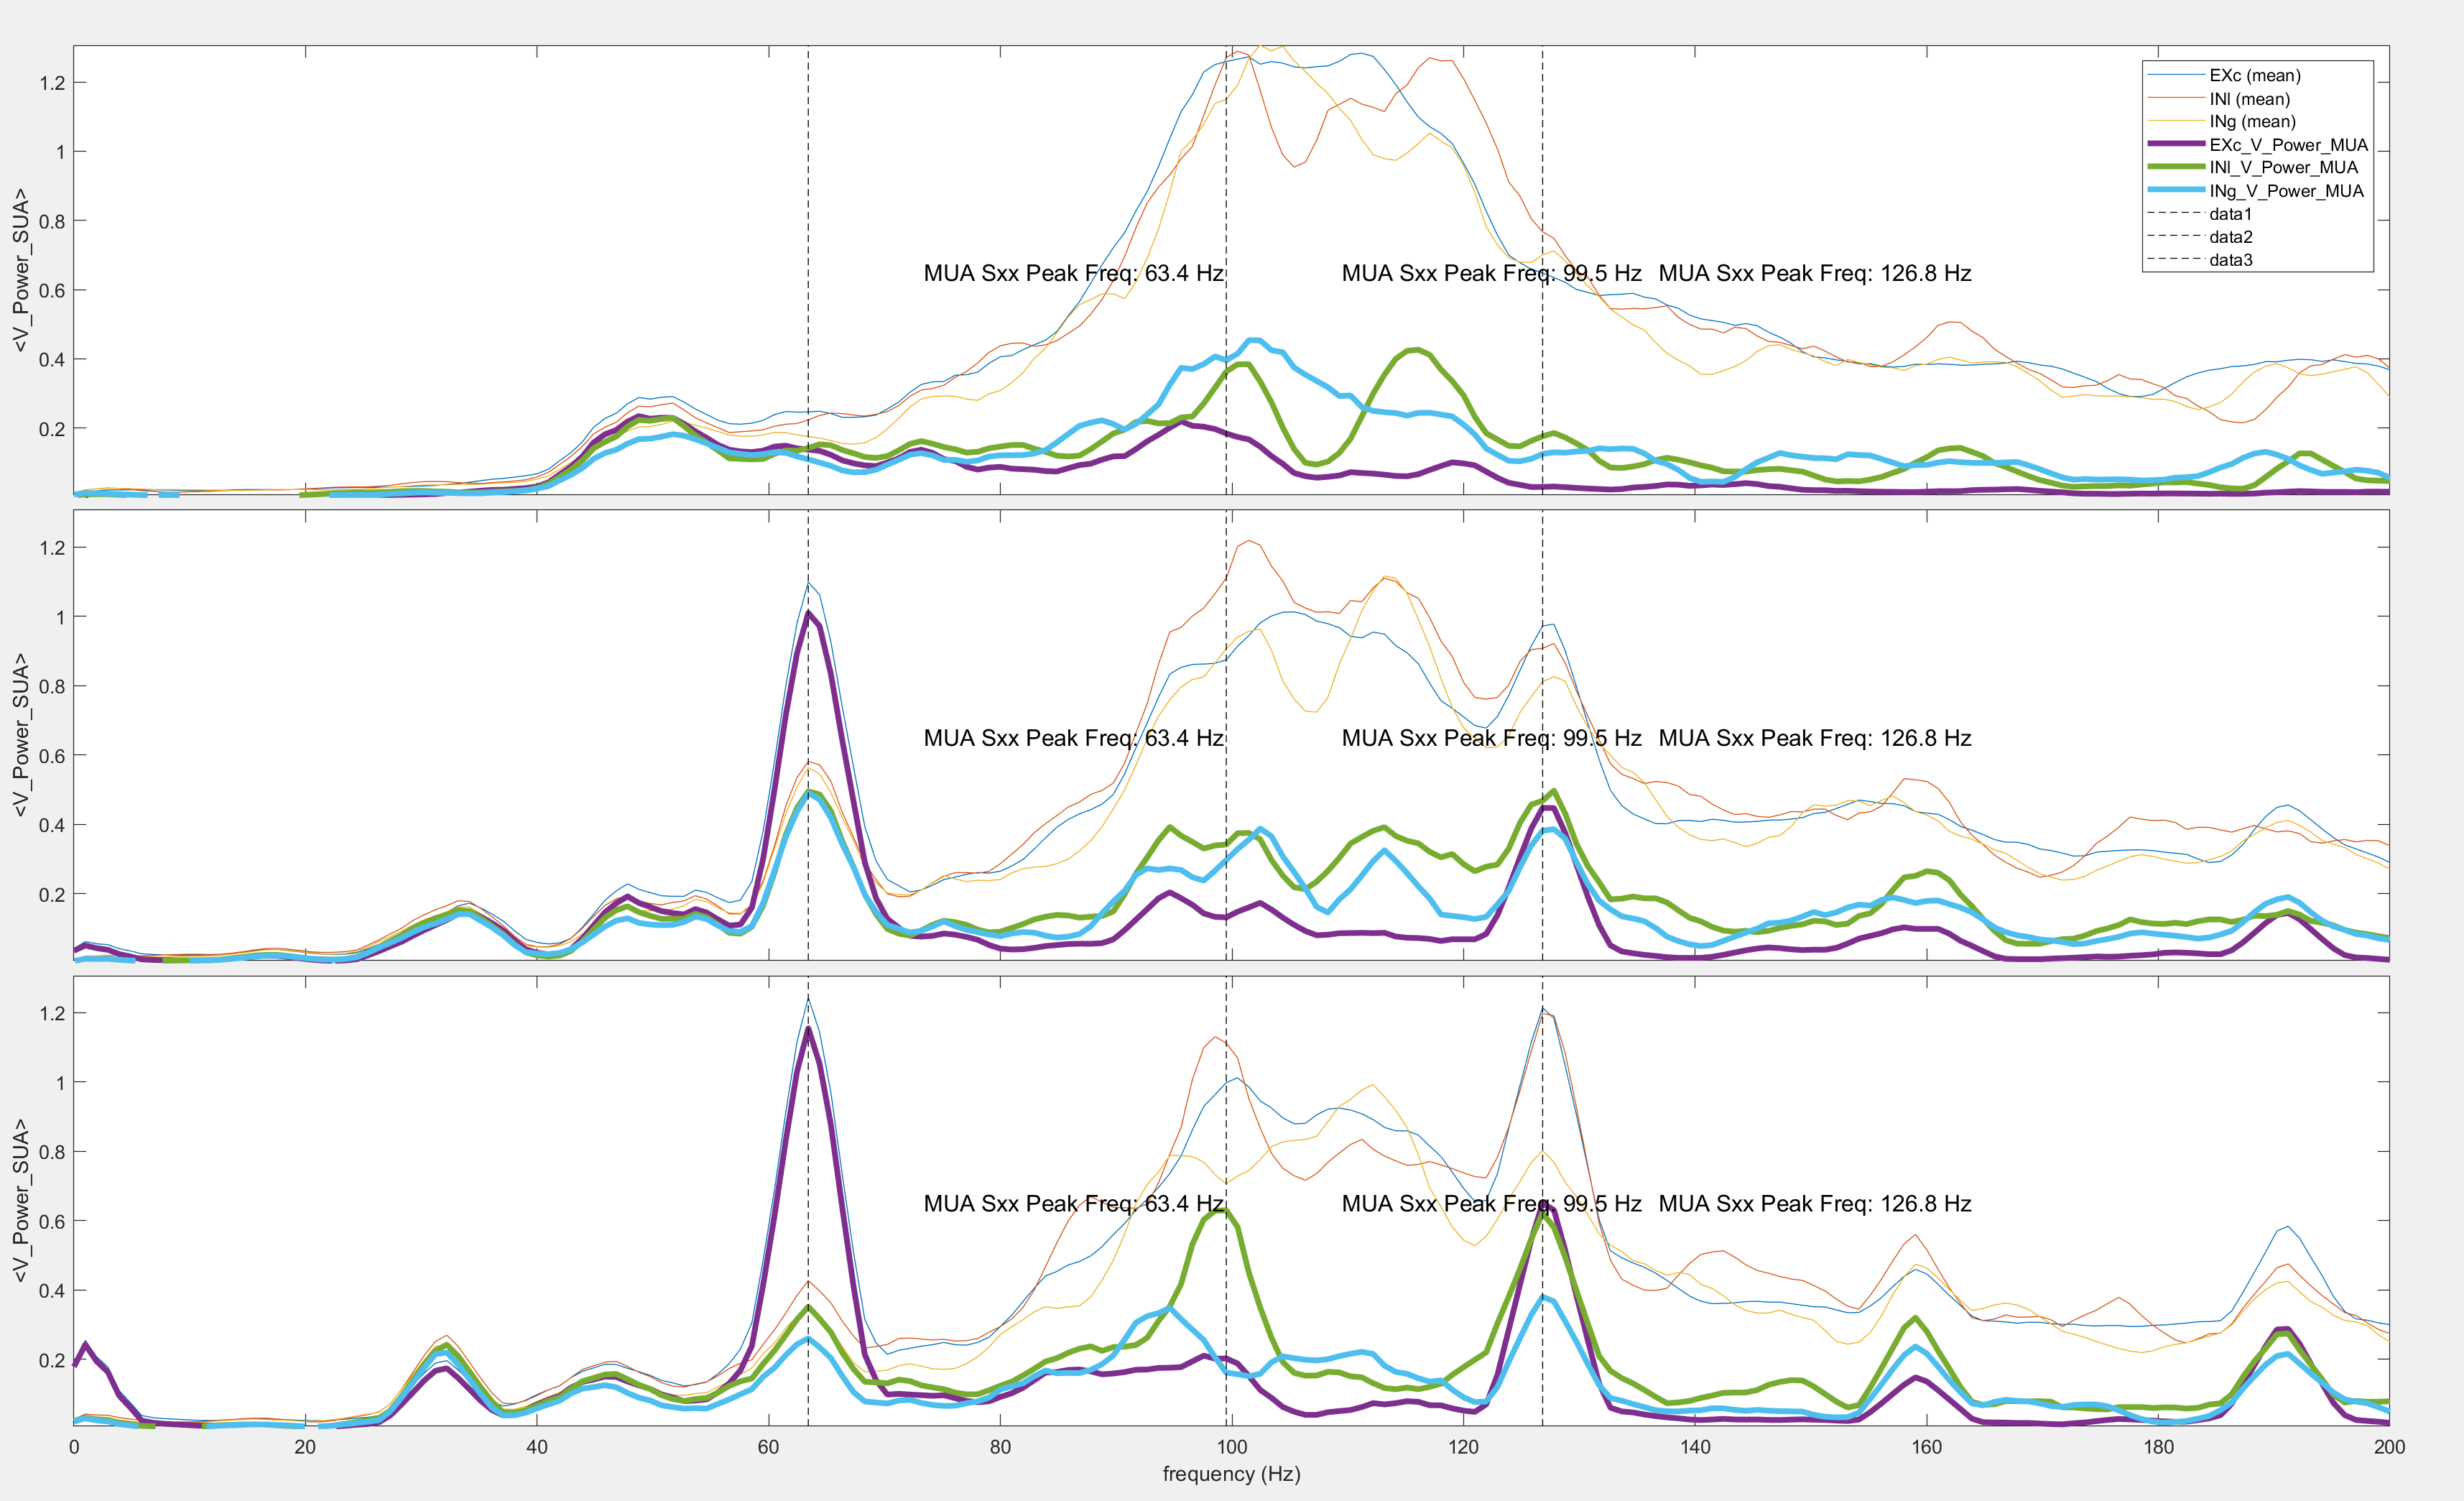

dsPlot(data, 'plot_type', 'power');

## 2. DynaLearn object initialization

dl = DynaLearn(s, study_dir, 'mex', 'PN', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:

PREPARING SOLVER:
Saving params.mat
Creating solver file: D:\Modeling\DynaSim\dlModels\PN13\solve\sim1\solve_ode_20250127192310_332.m
Compiling file: D:\Modeling\DynaSim\dlModels\PN13\solve\sim1\solve_ode_20250127192310_332.m
            to: D:\Modeling\DynaSim\dlModels\PN13\solve\sim1\solve_ode_20250127192310_332_mex
Code generation successful.

    MEX generation complete! 
    Elapsed time: 1.3 minutes. 
    Removing


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/PN13/dlFile.mat".


- Loader function; if the model already exists.

id = 14;
dl = DynaLearn.dlLoader(char("dlModels/PN" + num2str(id)));

DL object loaded from dlModels/PN13 
Params.mat file loaded from dlModels/PN13 
--------
--->Constructing graph ... Done.

Reinitialized.


x = load("matdata\PoGLO_Ca_0818_MTMST.mat").y;
x = x.sigsb2l;

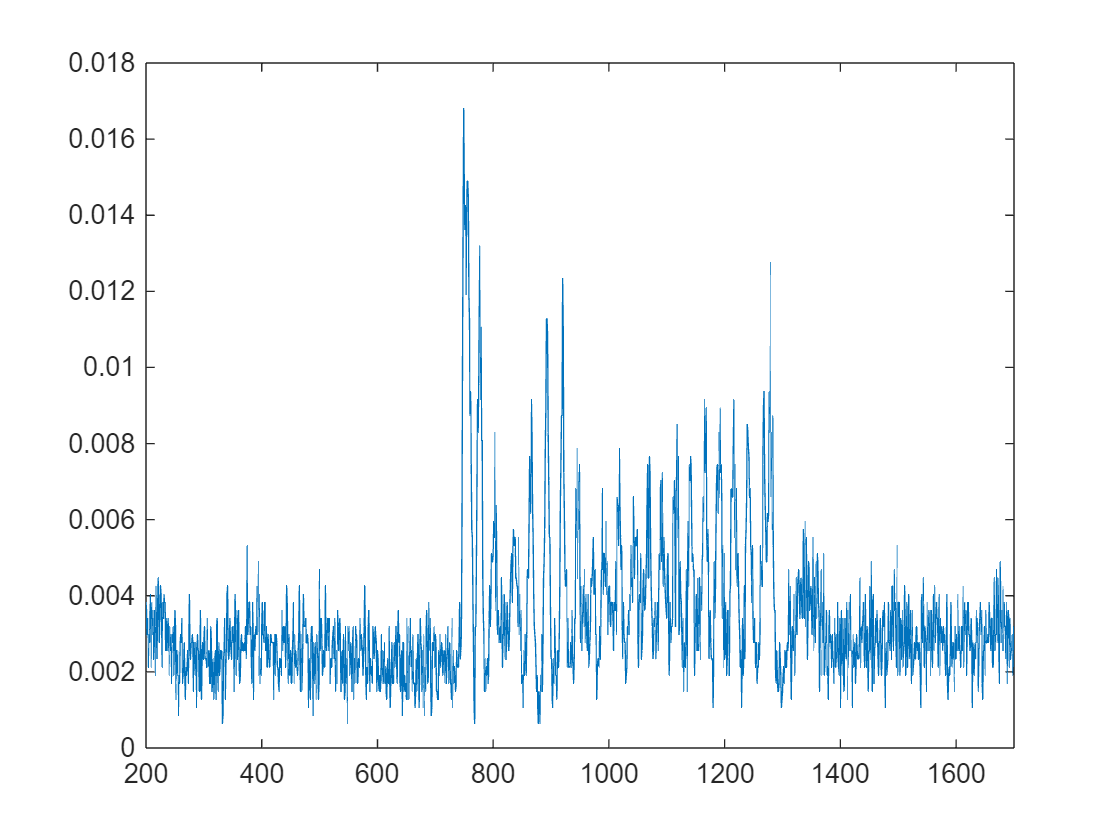

% trial = 2;
a = squeeze(mean(mean(x(1:100, 31:77, 301:2200), 1), 1));

% gNeurons [45:50, 65:70]
% a = squeeze(mean(mean(x(1:100, [41, 67], 501:2000), 1), 1));
% aa = sum(a, 2);
% a = a(aa < 5, :);
% aS = squeeze(x(trial, 1:80, 1:3000));

plot(mean(a, 1));xlim([200 1700]);

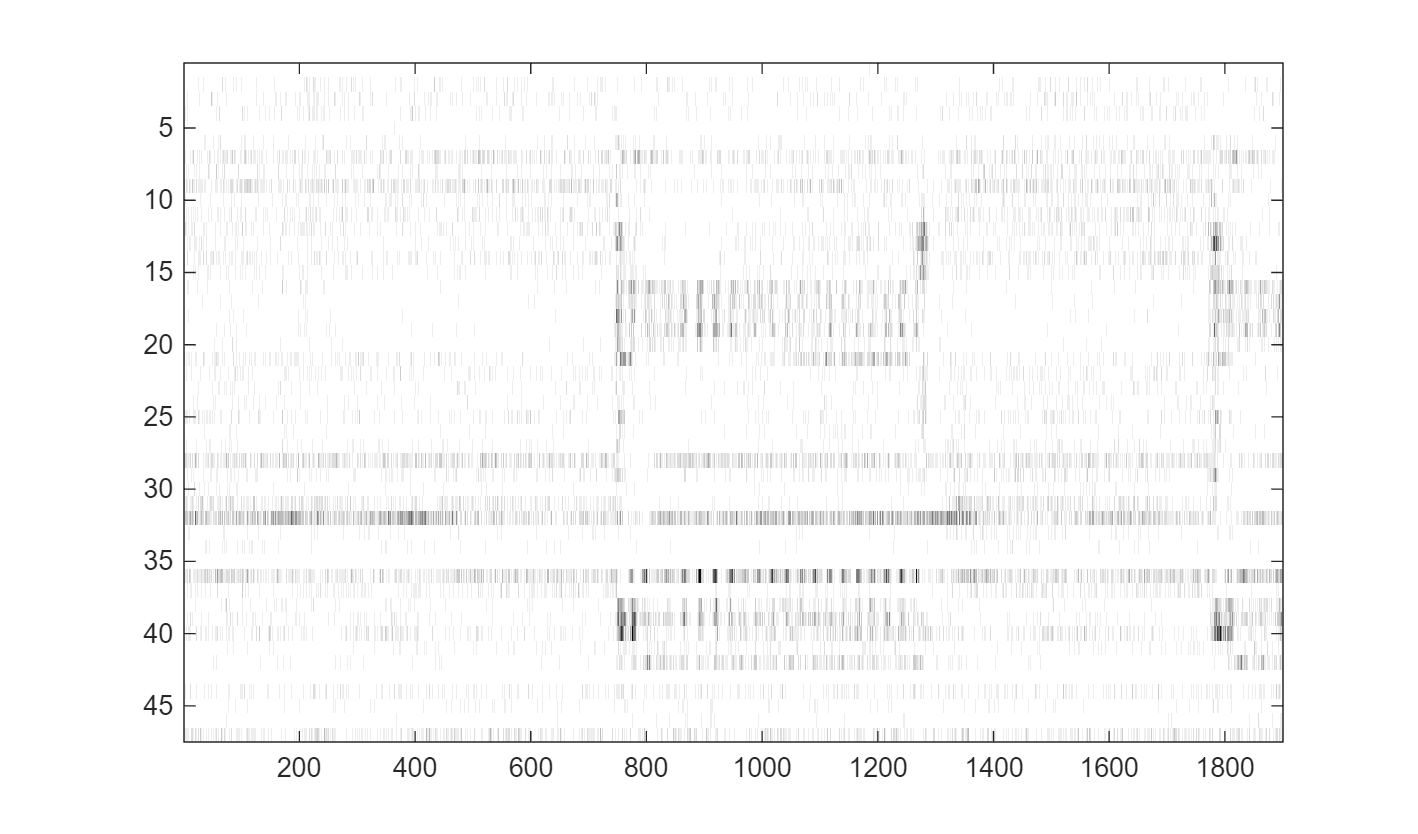

figure("Position", [0 0 1700 1000]);
imagesc(1-a);colormap("gray");

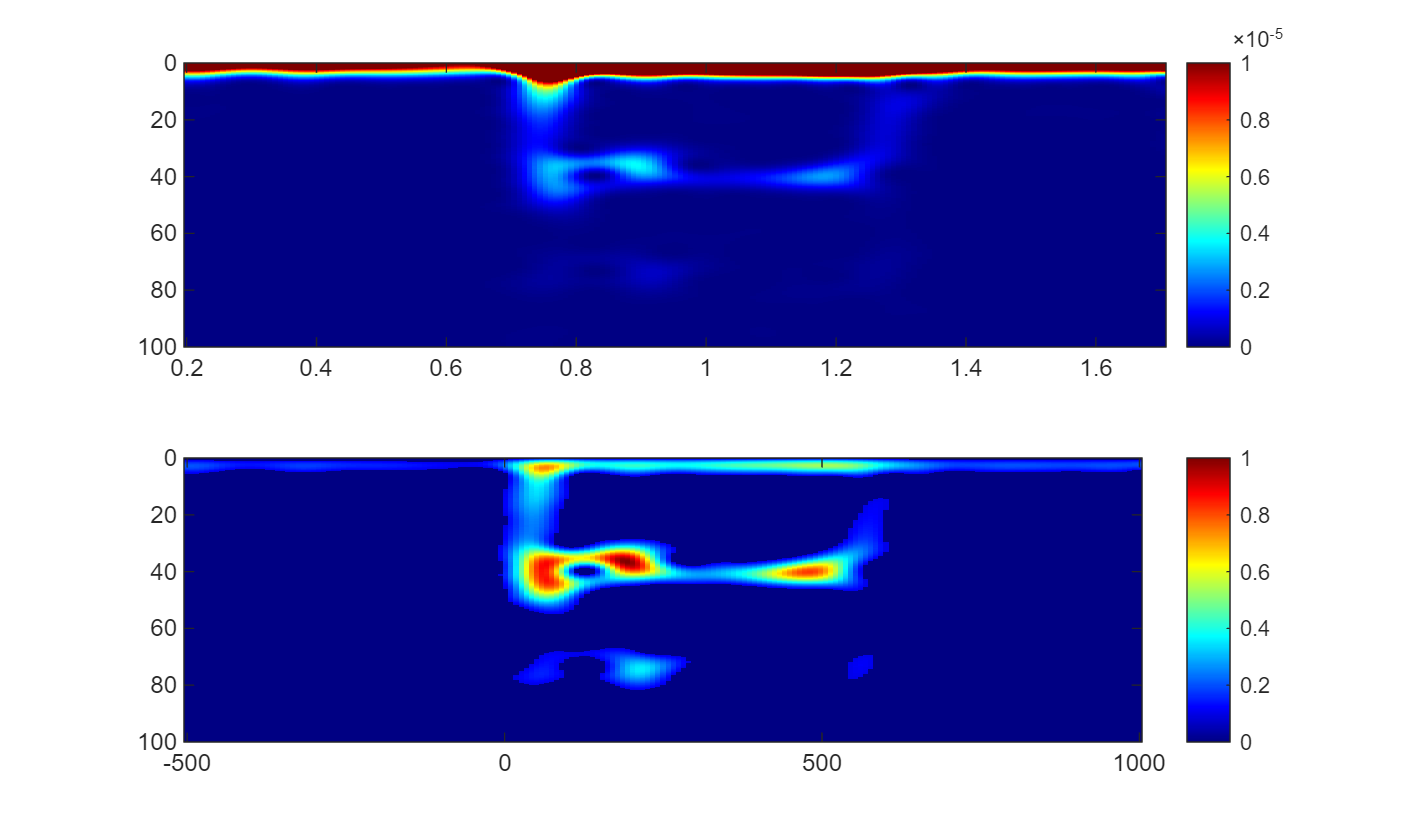

% xlim([500 2000]);
% [b, t, f] = dlSpectrogramPlot(a, 400, 1, 390, 60, 1000, 10, 0);

[b, f, t] = pspectrum(mean(a, 1), 1000, "spectrogram", ...
    "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 98);

figure("Position", [0 0 1700 1000]);
subplot(2, 1, 1);
imagesc(b, "XData", t, "YData", f);colormap("jet");
colorbar();
clim([0 1e-5])
targetVsgram = b;

for ik = 1:size(targetVsgram, 1)

    targetVsgram(ik, :) = targetVsgram(ik, :) * ik;

end

targetVsgram = (targetVsgram / max(max(targetVsgram)));
targetVsgram = (targetVsgram - mean(min(targetVsgram)));
targetVsgram = targetVsgram / max(max(targetVsgram));
targetVsgram(targetVsgram < 0.1) = 0.0;
% wnsq = ceil(sqrt(size(targetVsgram, 2))); 
% targetVsgram = conv2(targetVsgram, onEx(1, wnsq), "same");

subplot(2, 1, 2);
imagesc(targetVsgram, "XData", -501:1000, "YData", f);
clim([0 1.0])
colorbar;

targetVsgram1 = targetVsgram(:, end-50:end);
targetVsgram2 = targetVsgram;

a1 = mean(targetVsgram(:, 1:22), 2);
a2 = mean(targetVsgram(:, 23:44), 2);
plot(linspace(0, 100, length(a1)), (a2-a1)./a1);
yline(0);

RunDuration = 1500;

[inp1, inp2] = dlOnOffInputs(RunDuration, 500, 1000, 30);
dlInputParameters = {inp2}; % Null inputs (no external stimulation).
dlOutputParameters = {['EXc', '_V'], 1:36, [1 RunDuration], 'afr'};
dlTargetParameters = {{{'LogCor2', 1, targetVsgram2, 1.0, 1, 100}; {'MXE', 1, 10, 1.0, 0, 0}}};

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure

dlTrainOptions('dlBatchs') = 1;
dlTrainOptions('dlLambda') = 1e-4; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 100; % Total iterations
dlTrainOptions('dlUpdateVerbose') = 1;

dlTrainOptions('dlExcludeDiverge') = 1; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 5;
dlTrainOptions('dlTrainIncludeList') = ["_netcon"];
dlTrainOptions('dlUpdateMode') = 'Batch';

% dlTrainOptions('dlTrainRestrictList') = "_netcon"; % Restrict list
% dlTrainOptions('dlTrainRestrictCoef') = {0.01}; % Restrict coeffs
% dlTrainOptions('dlTrainRestrictBound') = {[0.2 10.0]};

dlTrainOptions('dlTrainExcludeList') = "_IC_noise";
% dlTrainOptions('dlTrainSyncList') = ["INl_noise", "INg_noise"];
dlTrainOptions('dlMIDP') = 0;
dlTrainOptions('dlCheckpointCoefficient') = 2.0;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-->Log flag for loss plot is not specified; default = 1.


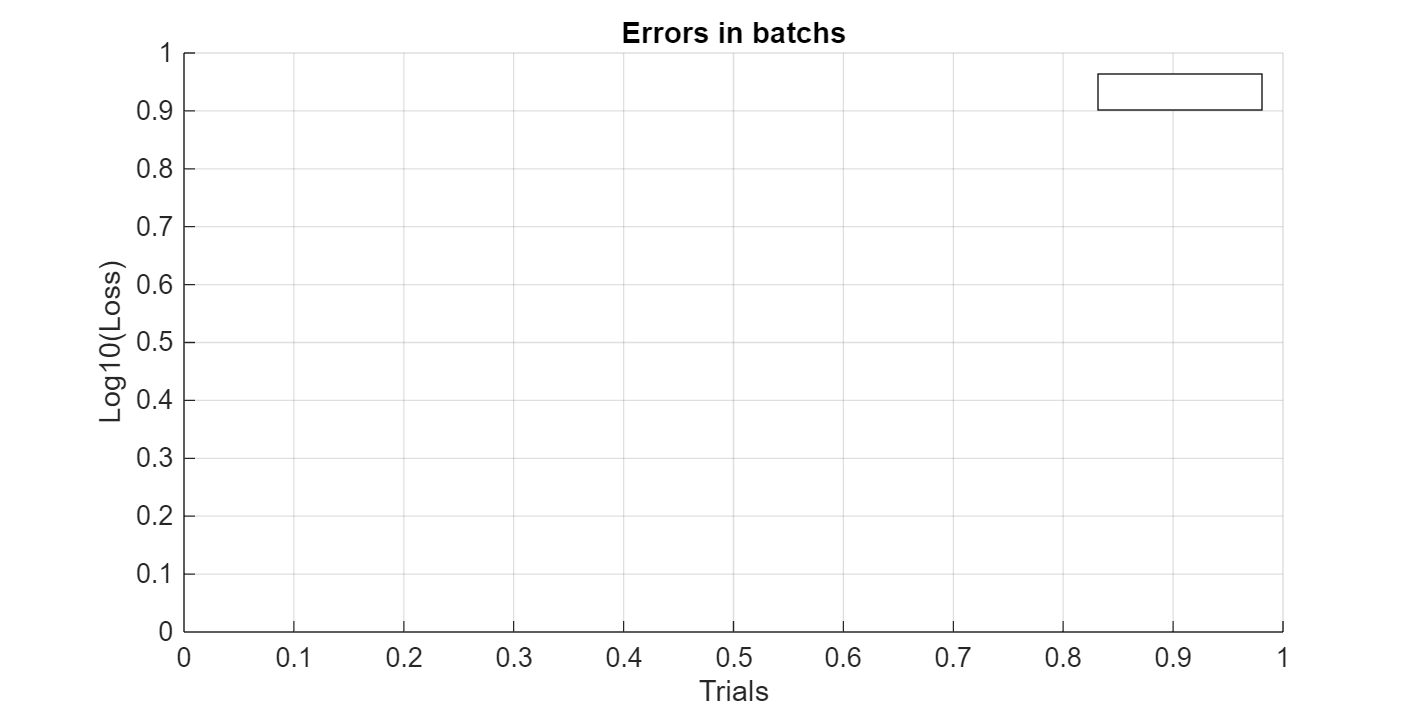

dl.dlPlotBatchErrors(2);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/PN13/Optimal 
---->Optimal [Parallel]


Condition1



	->Single trial running: 
Updating parameters of dlModels/PN13/solve > 

	->Done.


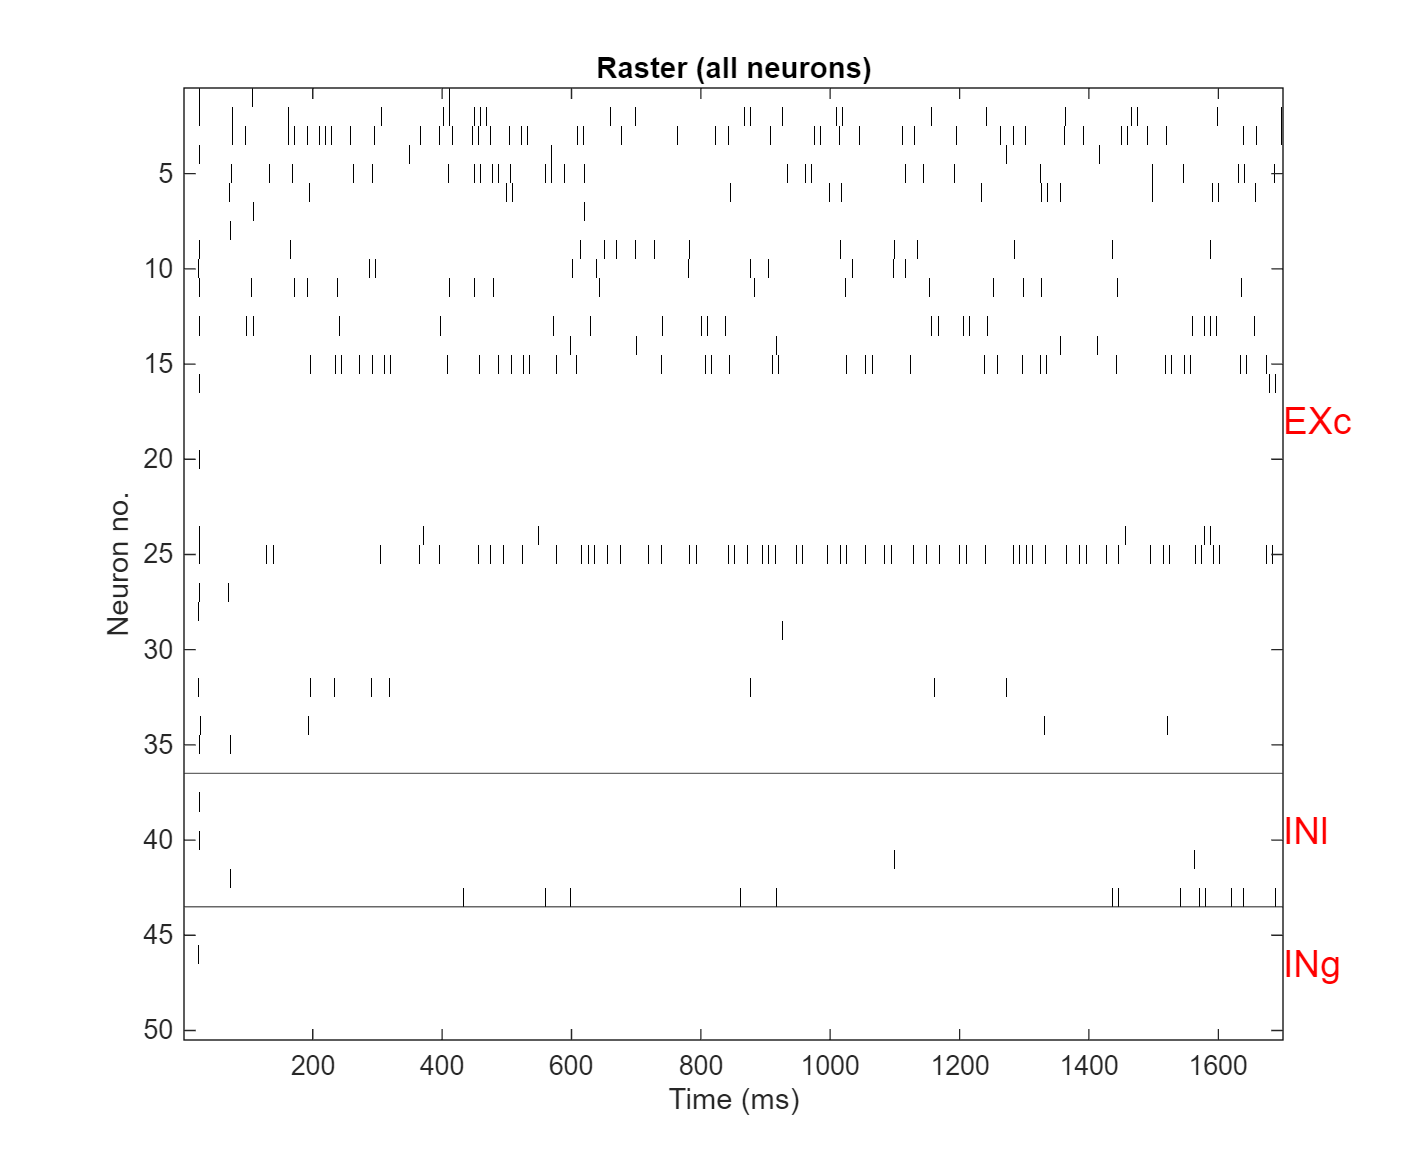

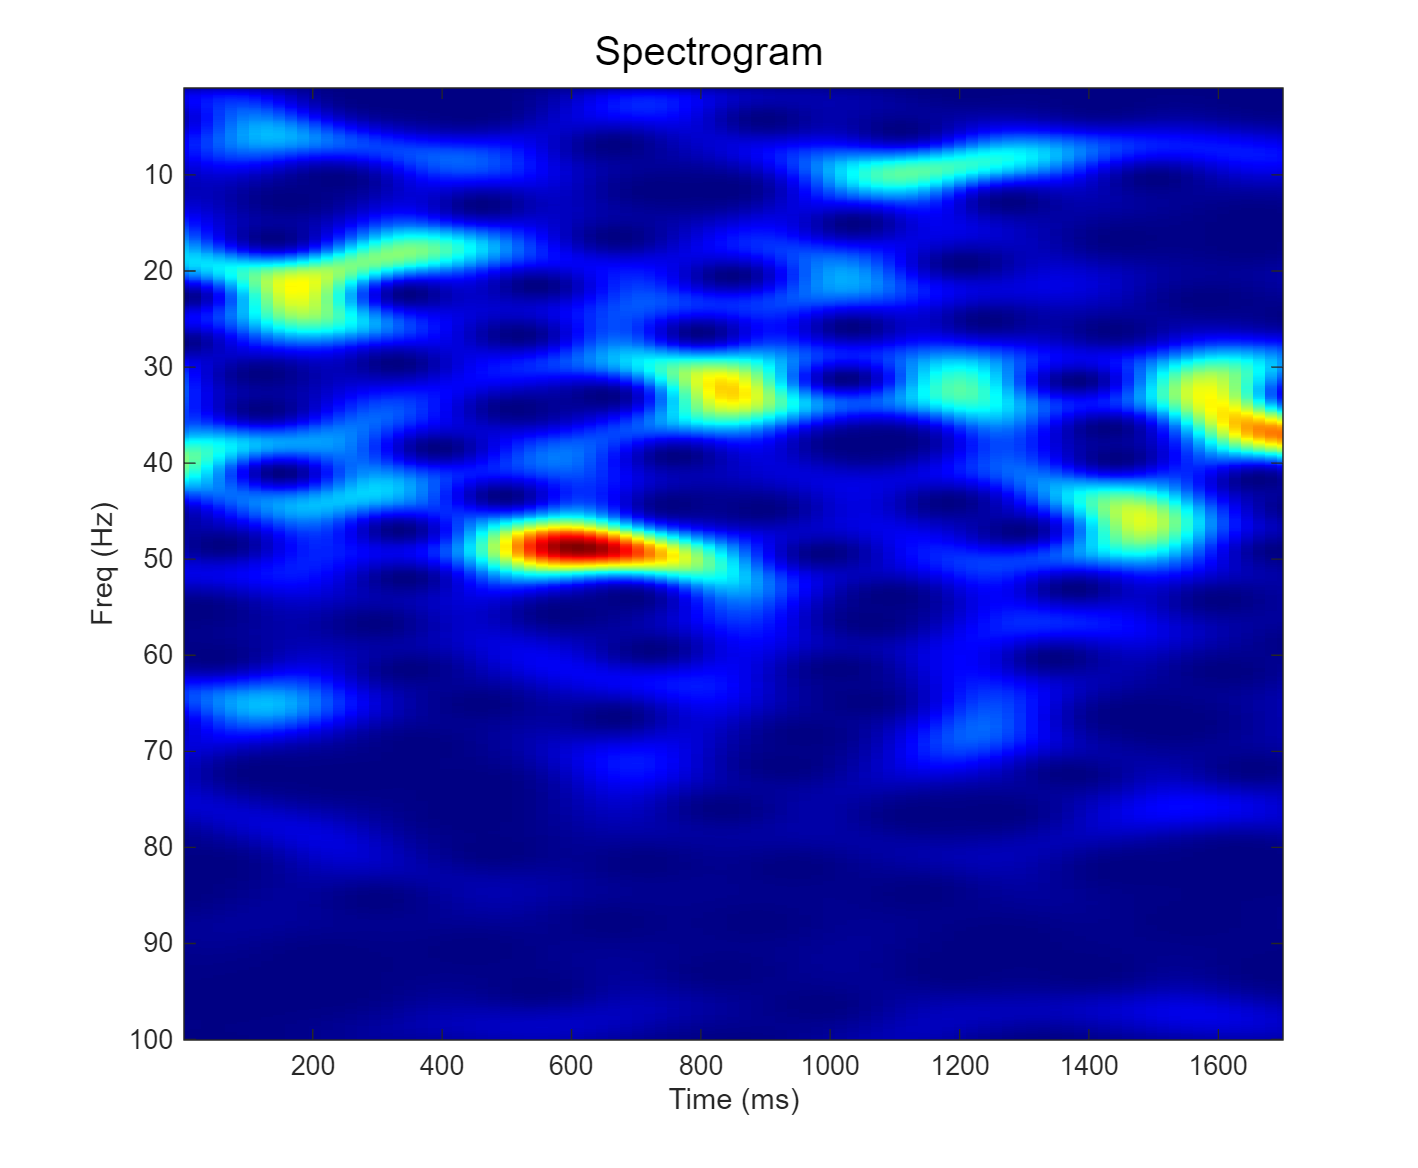

Condition2



	->Single trial running: 
Updating parameters of dlModels/PN13/solve > 

	->Done.


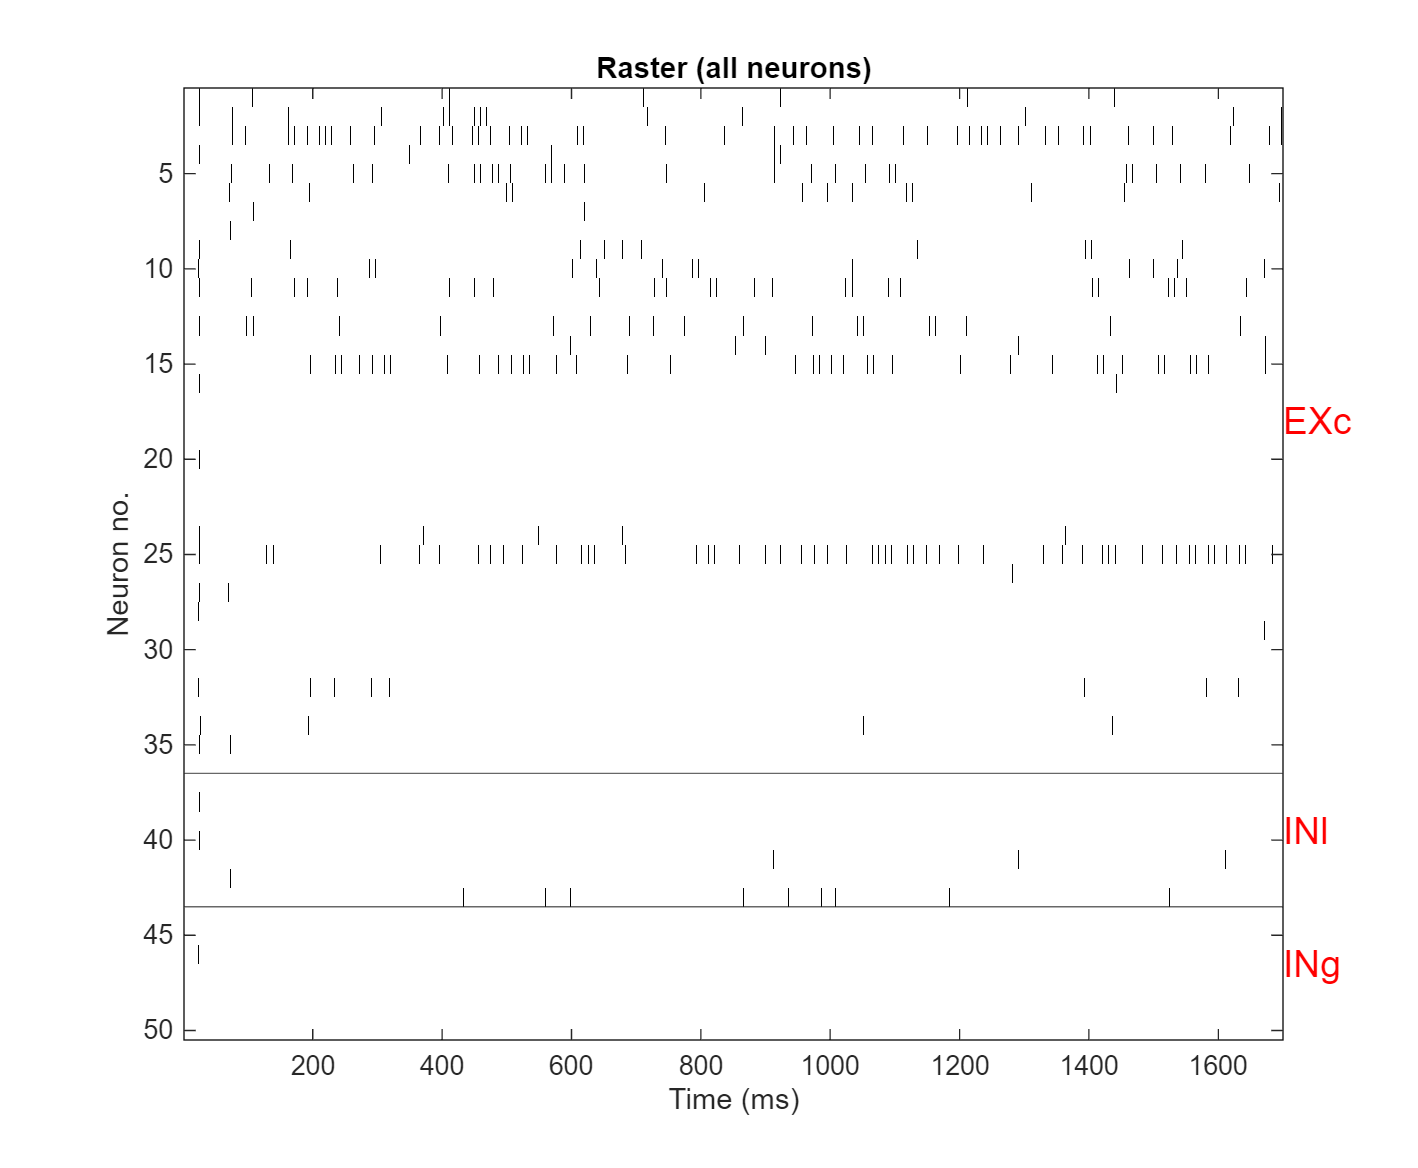

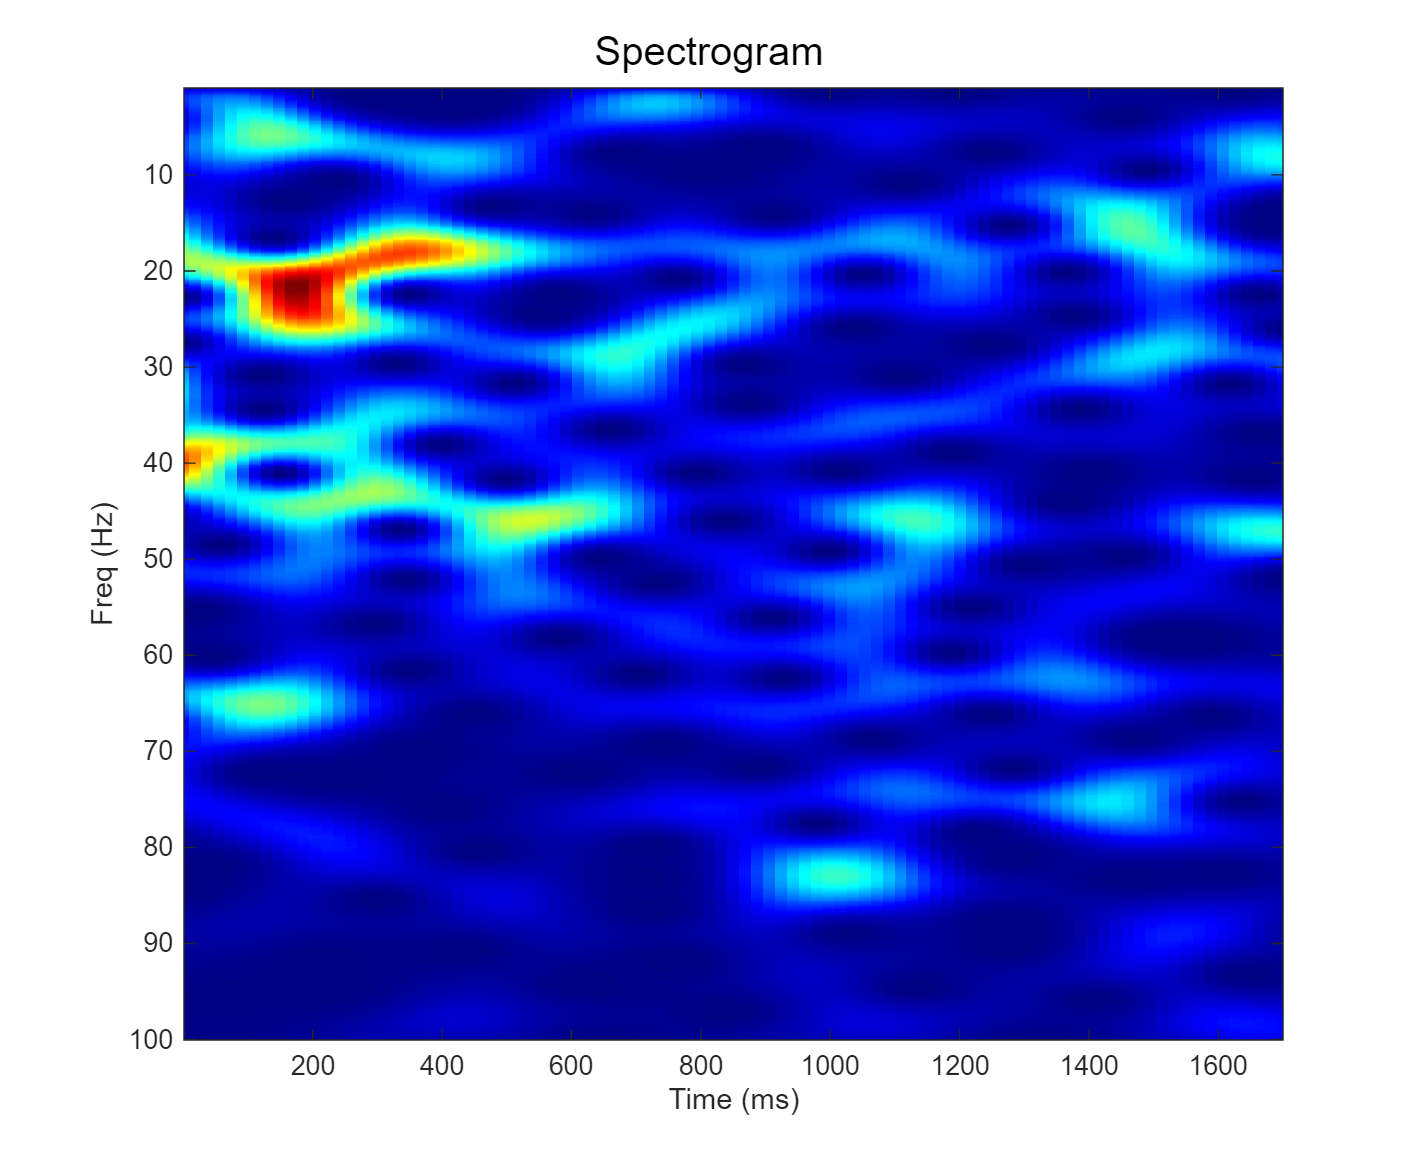

Condition3



	->Single trial running: 
Updating parameters of dlModels/PN13/solve > 

	->Done.


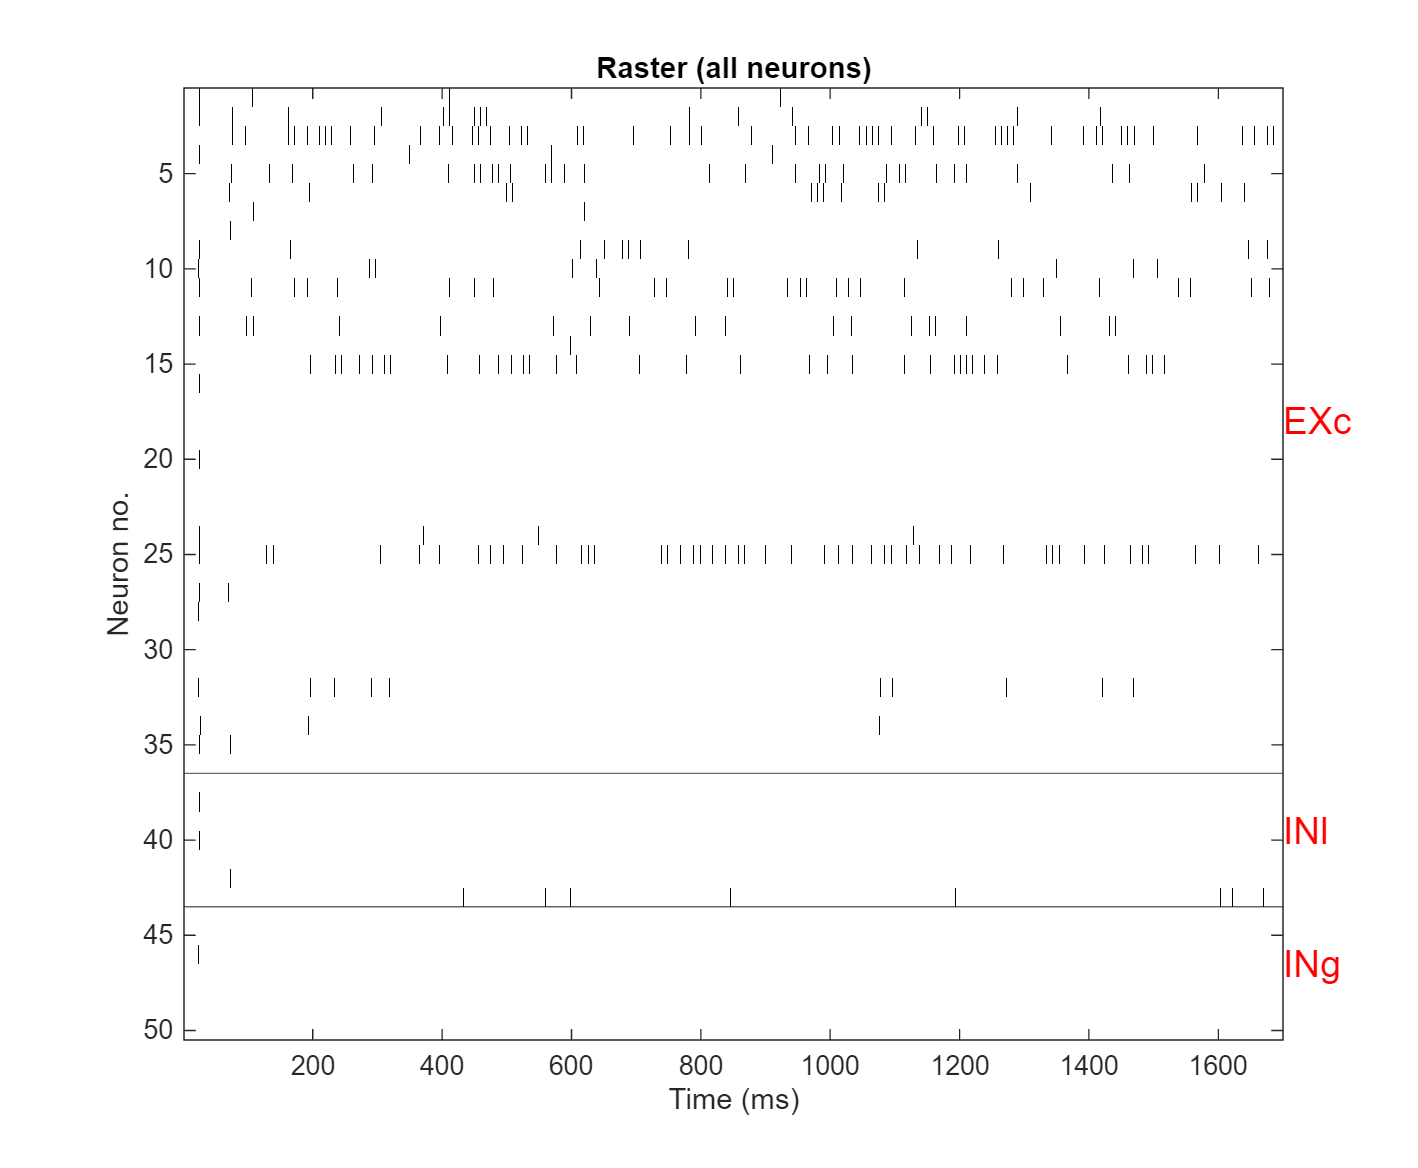

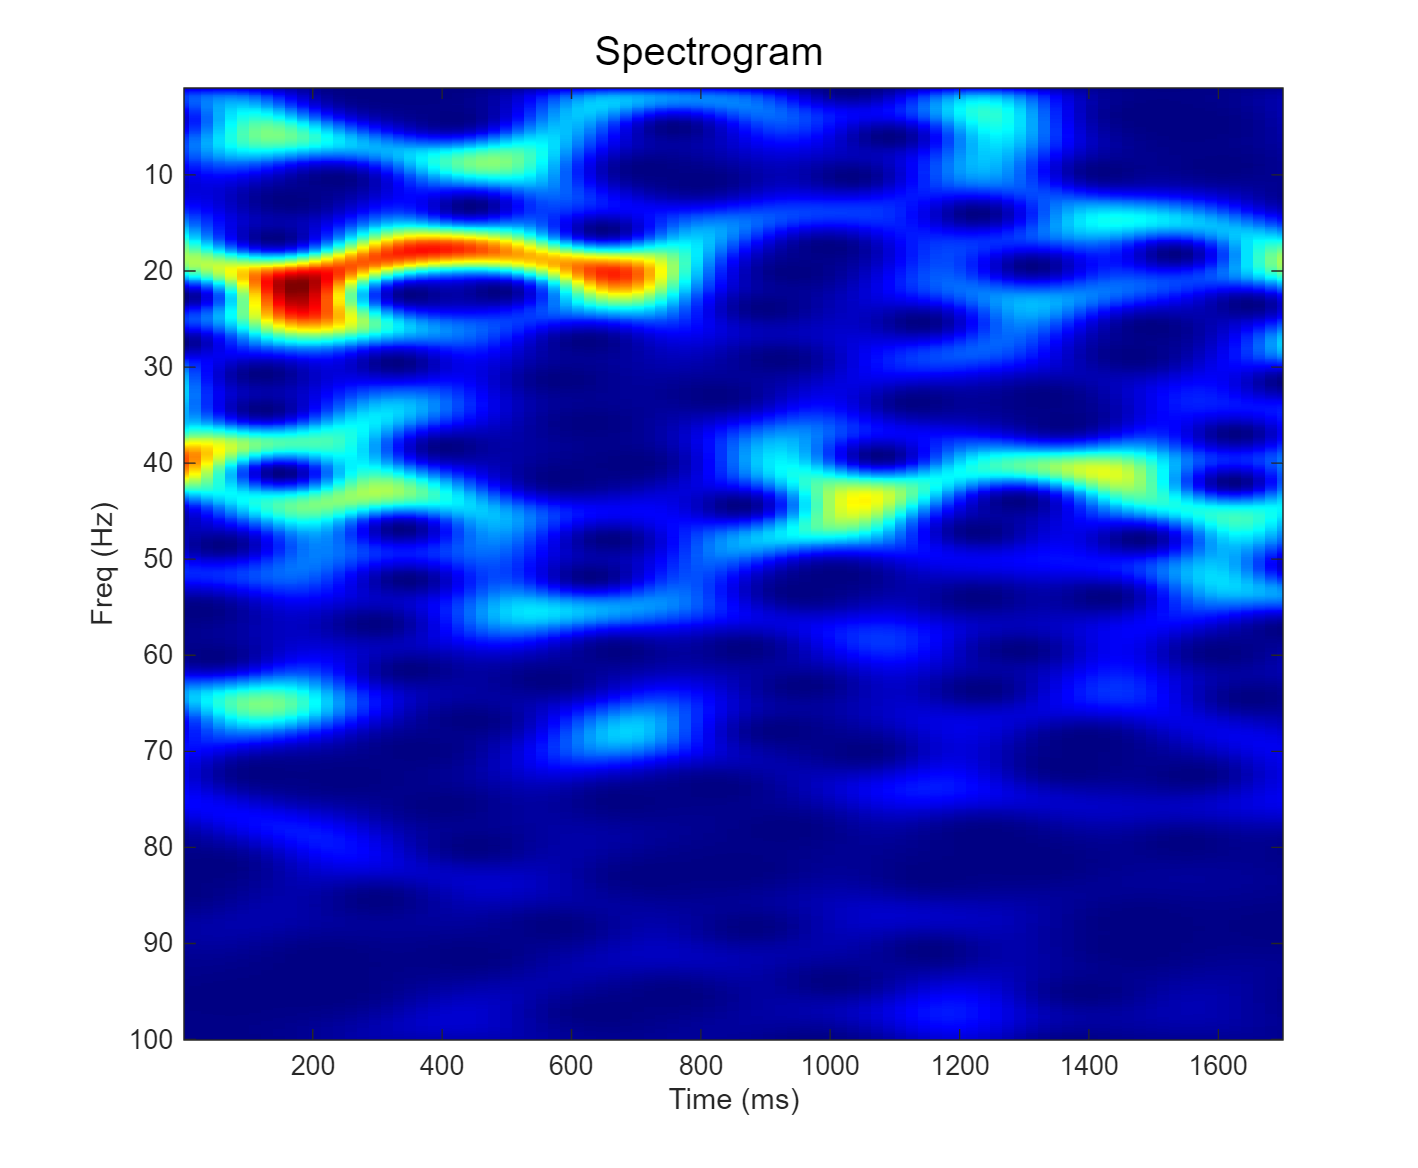

Condition4



	->Single trial running: 
Updating parameters of dlModels/PN13/solve > 

	->Done.


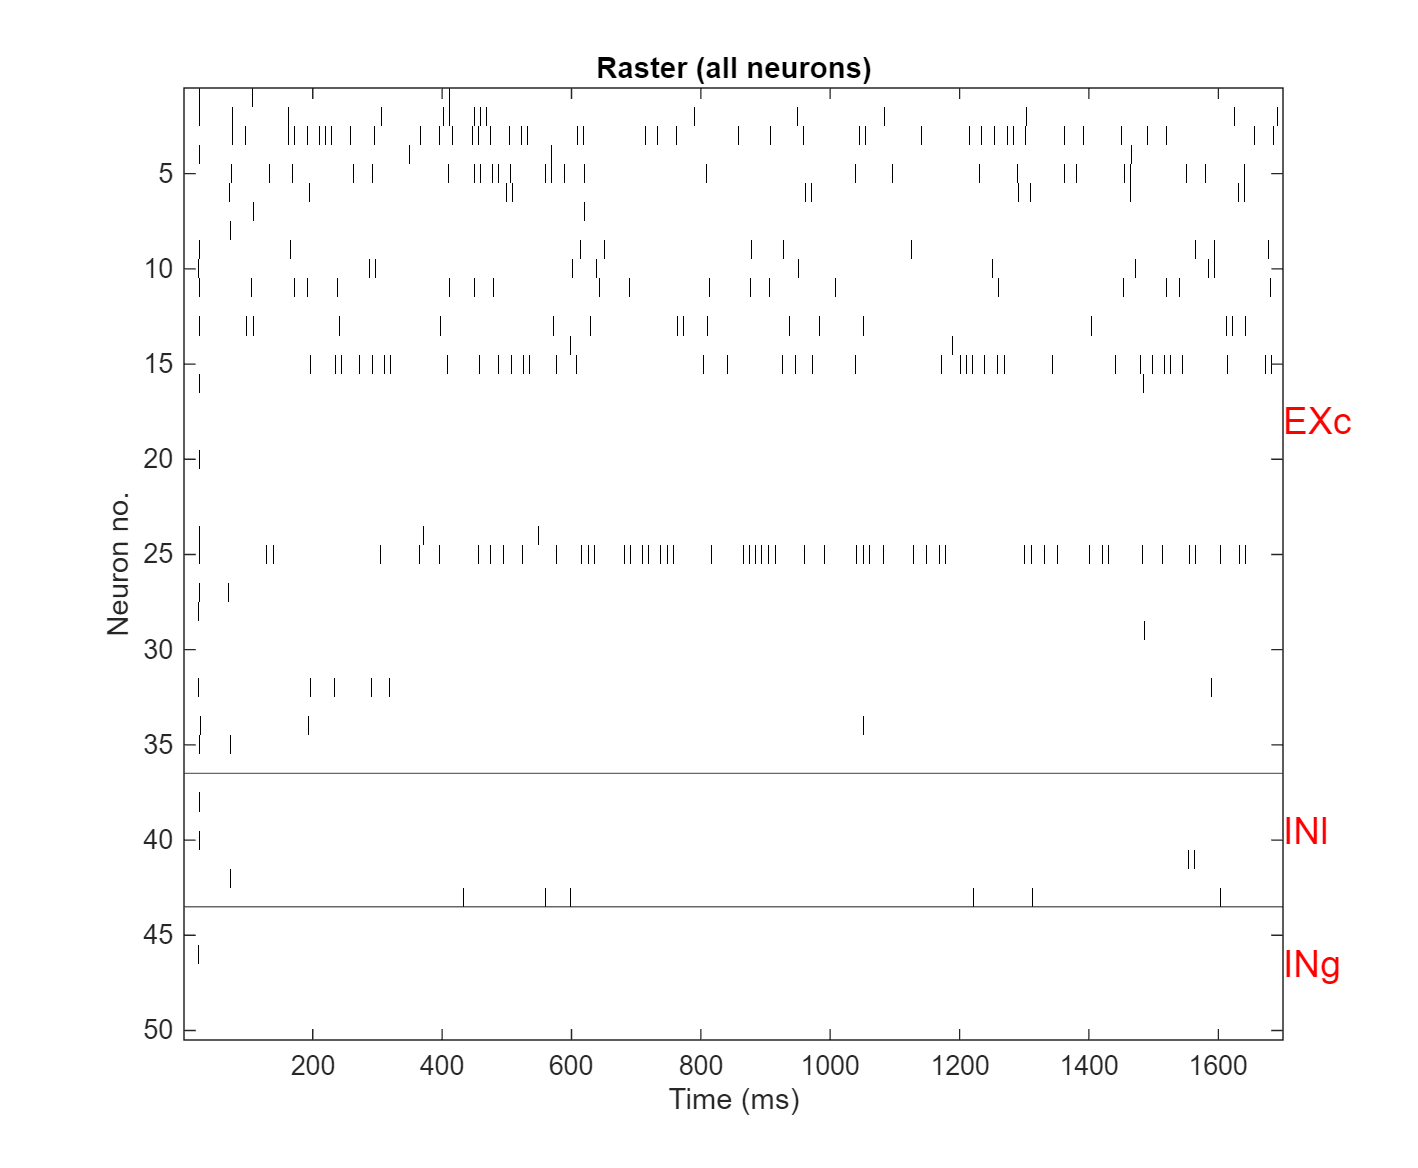

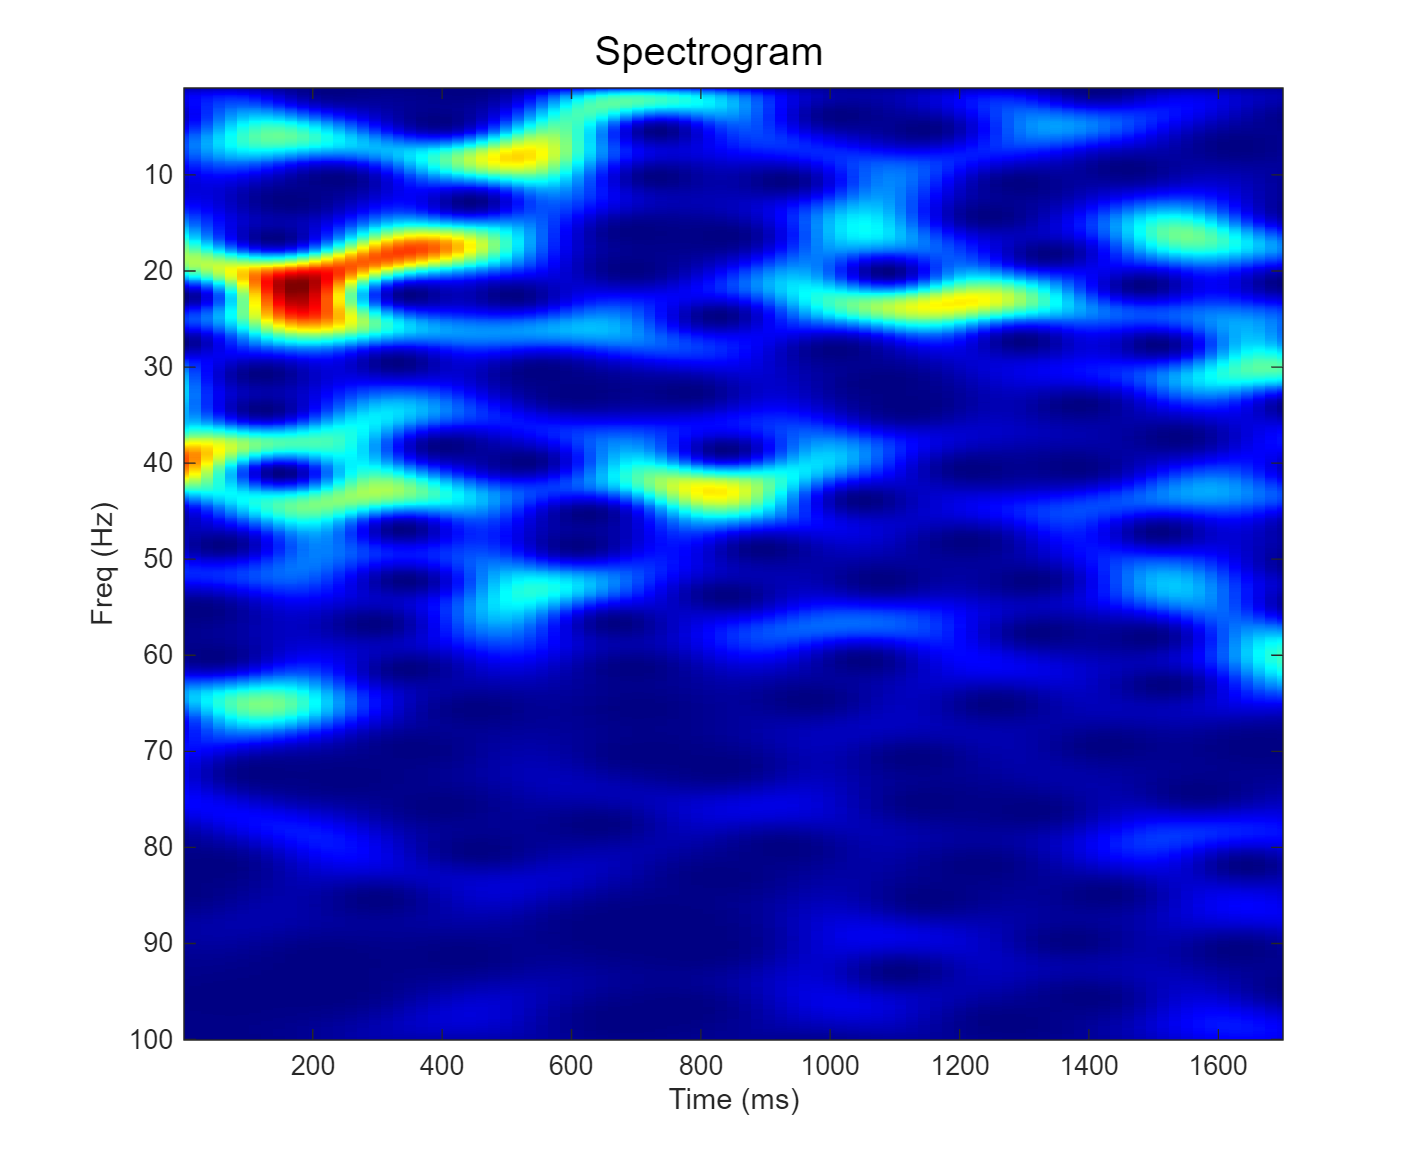

Condition5



	->Single trial running: 
Updating parameters of dlModels/PN13/solve > 

	->Done.


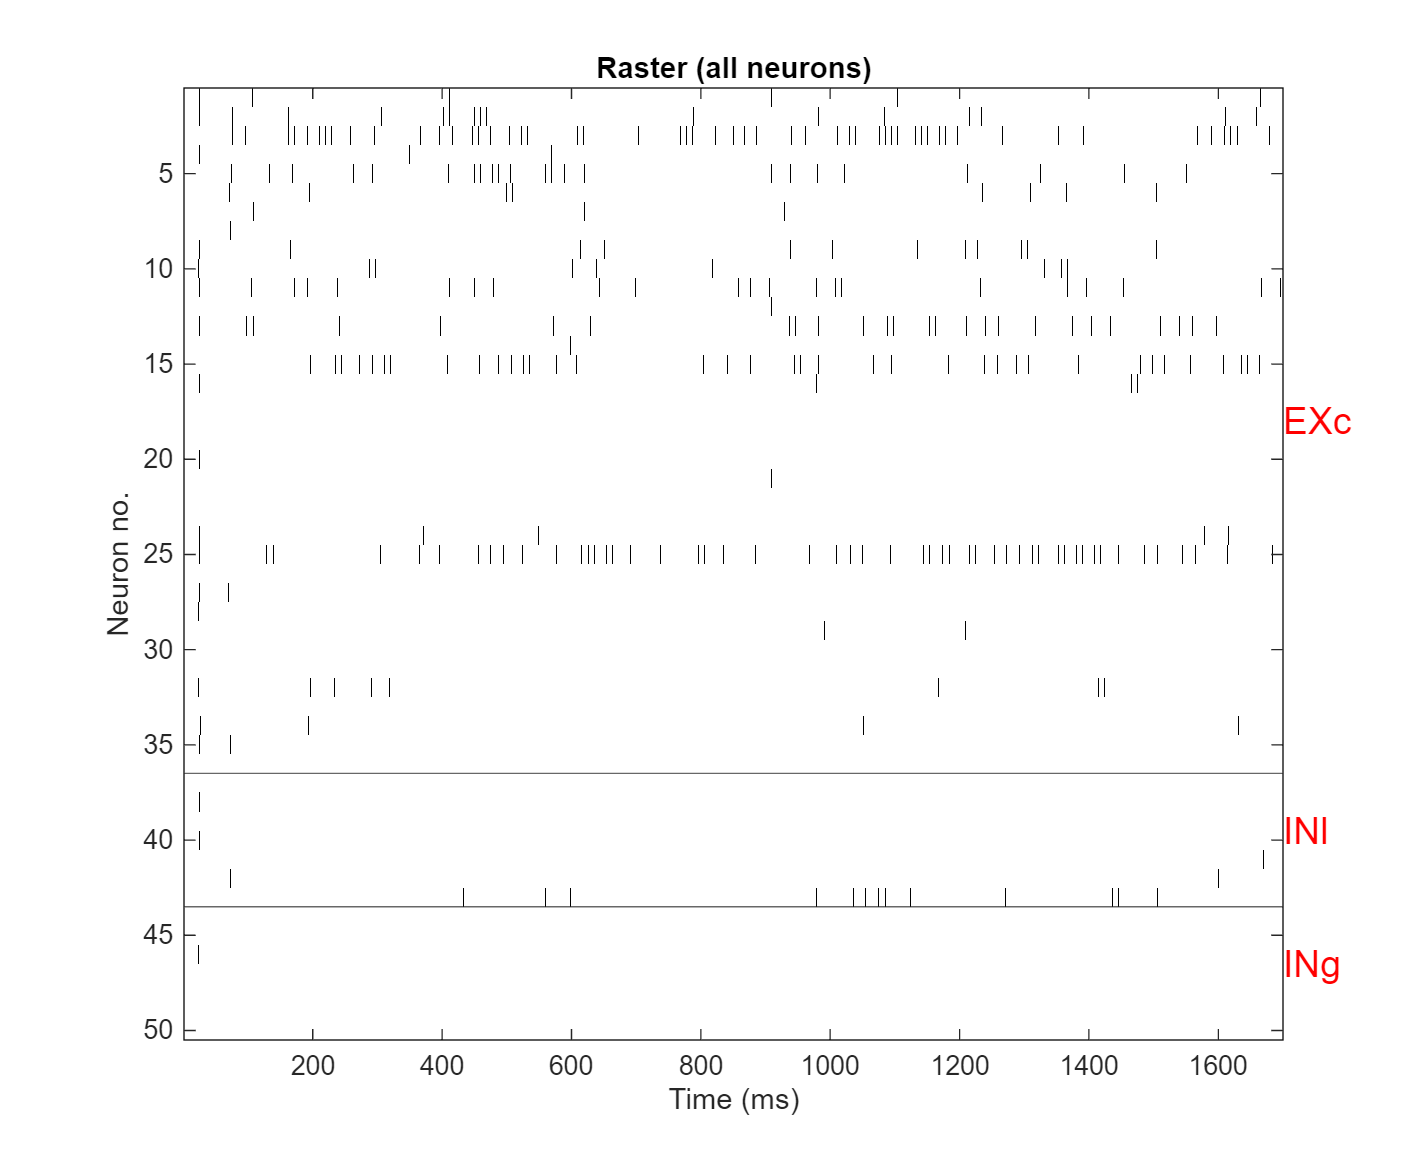

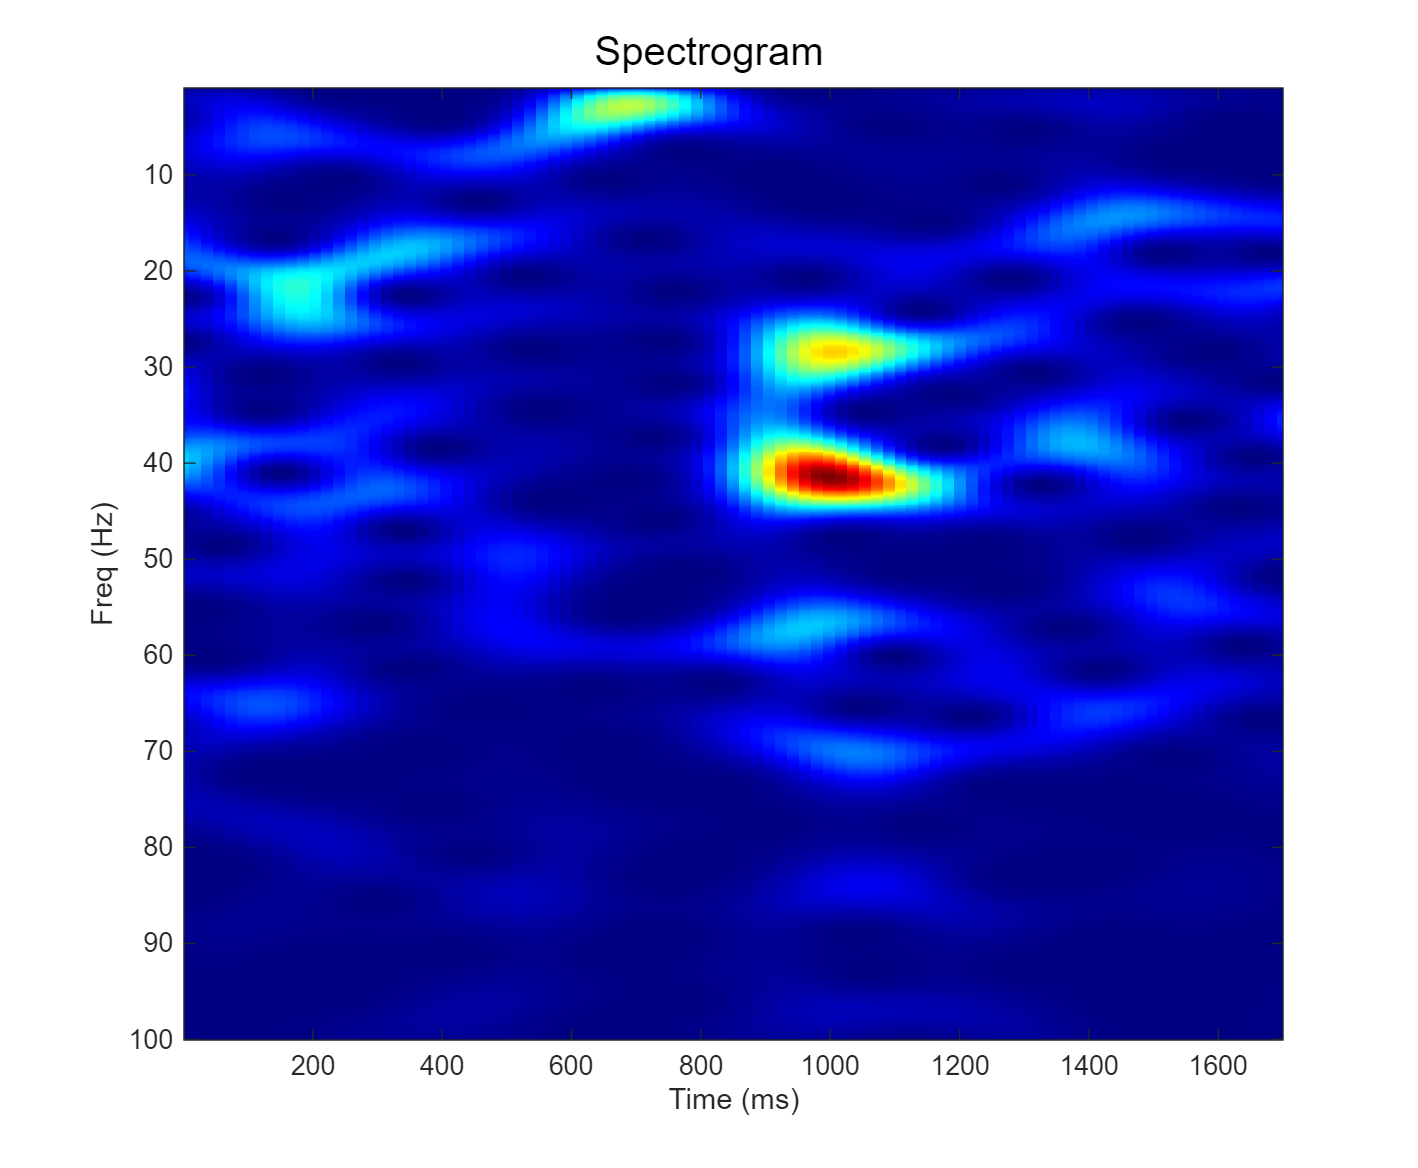

RunDuration = 1700;
ng = 5;
dlInputParameters2 = dlGradedInputs(RunDuration, 650, 900, 20, ng);

xlims = [1 1700];
clims = [0 1.0];

for i = 1:ng%max(size(dlInputParameters, 2))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters2{i});%, dlOutputParameters);
    dl.dlRaster(xlims, -10);
    dl.dlSpectrogram(200, 1, 190, 100, xlims, clims);

end

figure("Position", [0 0 1700 1100]);
subplot(1, 2, 1);
imagesc(rand([50, 50]));
colorbar();

subplot(1, 2, 2);
imx = zeros([50, 50]);
imx(1:36, 1:36) = dl.dlParams.EXc_EXc_iAMPA_netcon;
imx(1:36, 37:43) = dl.dlParams.INg_EXc_iAMPA_netcon;
imx(1:36, 44:50) = dl.dlParams.INl_EXc_iAMPA_netcon;
imx(37:43, 1:36) = dl.dlParams.EXc_INg_iGABAa_netcon;
imx(37:43, 37:43) = dl.dlParams.INg_INg_iGABAa_netcon;
imx(37:43, 44:50) = dl.dlParams.INl_INg_iGABAa_netcon;
imx(44:50, 1:36) = dl.dlParams.EXc_INl_iGABAa_netcon;
imx(44:50, 37:43) = dl.dlParams.INg_INl_iGABAa_netcon;
imx(44:50, 44:50) = dl.dlParams.INl_INl_iGABAa_netcon;

imagesc(imx);
colorbar();

[b] = dlSpectrogramPlot(dl.dlSignals, 200, 1, 190, 100, 1000, 11, 0);
b(b < 0.2) = 0.1;

figure("Position", [0 0 1700 1000]);
imagesc(b);colormap("jet");

a = dl.dlSignals;
a = (1 - a) > 4;
y = zeros(size(a));

for i = 1:size(a, 1)

    tempX = a(i, :);
    tempX = conv(tempX, exp(linspace(1, 0, 70)), "same");
    y(i, :) = tempX;

end

y = zeros(size(a));

for i = 1:size(a, 1)

    tempX = a(i, :);
    tempX = conv(tempX, exp(linspace(1, 0, 70)), "same");
    y(i, :) = tempX;

end

figure;
plot(linspace(0, 3000, 3000), -mean(y, 1));

a = struct();
a.L1.E = 10;
a.L1.PV = 1;
a.L1.CB = 2;
a.L1.CR = 3;

y1 = zeros(size(x, 1), size(x, 2), 100);
y2 = zeros(size(x, 1), size(x, 2), 100);

t_on = 1001:2000;
t_off = 5001:6000;

for i = 1:size(x, 1)

    for j = 1:size(x, 2)

        w = squeeze(x(i, j, t_on));
        y1(i, j, :) = dlSpectrum(w, 1000, 100, 100, 0);
        w = squeeze(x(i, j, t_off));
        y2(i, j, :) = dlSpectrum(w, 1000, 100, 100, 0);

    end

end

targetVspectrum1 = mean(squeeze(mean(y1, 1)), 1);
targetVspectrum2 = mean(squeeze(mean(y2, 1)), 1);
targetVspectrum1 = targetVspectrum1 - min(targetVspectrum1);
targetVspectrum2 = targetVspectrum2 - min(targetVspectrum2);

targetVspectrum1 = targetVspectrum1 / max(targetVspectrum1);
targetVspectrum2 = targetVspectrum2 / max(targetVspectrum2);

targetVspectrum1(targetVspectrum1 < 0.05) = 0.05;
targetVspectrum2(targetVspectrum2 < 0.05) = 0.05;

figure("Position", [0 0 1500 500]);
subplot(2, 1, 1);
plot(targetVspectrum1(1:100));
title("Stim on");
subplot(2, 1, 2);
plot(targetVspectrum2(1:100));
title("Stim off");

## End